# Partie taux d'intérêt:

Les données utilisées dans cette section de calibration sont constituées exclusivement de la courbe OIS CAD, extraite d’une courbe générique Bloomberg (fonction $\texttt{GC}$) observée à la date du 2 avril 2026. Les quotes mid exportées sont interprétées comme des taux nodaux de la structure par terme.

Dans cette implémentation, ces taux sont convertis en facteurs d’actualisation nodaux via$\[
P(0,T_i)=\exp(-z_iT_i),
\]$où $\(z_i\)$ désigne le taux nodal en décimal associé à la maturité $ \(T_i\)$.

tenorStr = string(CADOISData.Tenor);
yPct = CADOISData.S147MidYTMCADOIS04_02_26Yield;
z = yPct / 100; %convertir en décimales

% On exprime les teneurs en années 

n = numel(tenorStr);
T = zeros(n,1);

for i = 1:n
    s = erase(string(tenorStr(i)), '"');
    num = str2double(extract(s, digitsPattern));
    
    if contains(s,"W")
        T(i) = num * 7 / 365;
    elseif contains(s,"M")
        T(i) = num / 12;
    else % cas "Y"
        T(i) = num;
    end
end

table(tenorStr, T, yPct, z)

ans = 25×4 table
    tenorStr       T        yPct        z   
    ________    ________    _____    _______

     "1W"       0.019178    2.272    0.02272
     "2W"       0.038356     2.27     0.0227
     "1M"       0.083333    2.274    0.02274
     "2M"        0.16667    2.282    0.02282
     "3M"           0.25    2.286    0.02286
     "4M"        0.33333    2.306    0.02306
     "5M"        0.41667    2.327    0.02327
     "6M"            0.5    2.355    0.02355
     "9M"           0.75    2.453    0.02453
     "1Y"              1    2.543    0.02543
     "18M"           1.5    2.654    0.02654
     "2Y"              2    2.719    0.02719
     "3Y"              3    2.796    0.02796
     "4Y"              4    2.848    0.02848
     "5Y"              5      2.9      0.029
     "6Y"              6    2.968    0.02968


[T, idx] = sort(T);
tenorStr = tenorStr(idx);
yPct = yPct(idx);
z = z(idx);

P0_nodes = exp(-z .* T); %les facteurs discount node

CurveTable = table(tenorStr, T, yPct, z, P0_nodes, ...
    'VariableNames', {'Tenor','MaturityYears','YieldPct','YieldDec','DiscountFactor'})

CurveTable = 25×5 table
    Tenor    MaturityYears    YieldPct    YieldDec    DiscountFactor
    _____    _____________    ________    ________    ______________

    "1W"       0.019178        2.272      0.02272        0.99956    
    "2W"       0.038356         2.27       0.0227        0.99913    
    "1M"       0.083333        2.274      0.02274        0.99811    
    "2M"        0.16667        2.282      0.02282         0.9962    
    "3M"           0.25        2.286      0.02286         0.9943    
    "4M"        0.33333        2.306      0.02306        0.99234    
    "5M"        0.41667        2.327      0.02327        0.99035    
    "6M"            0.5        2.355      0.02355        0.98829    
    "9M"           0.75        2.453      0.02453        0.98177    
    "1Y"              1        2.543      0.02

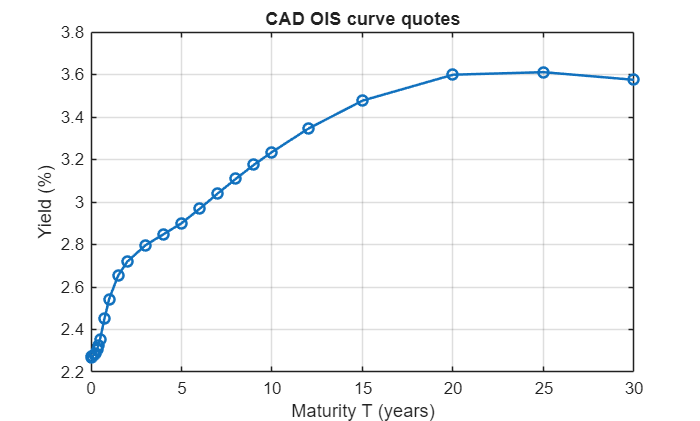

% On visualise quoted yields

figure;
plot(T, 100*z, 'o-', 'LineWidth', 1.5);
xlabel('Maturity T (years)');
ylabel('Yield (%)');
title('CAD OIS curve quotes');
grid on;

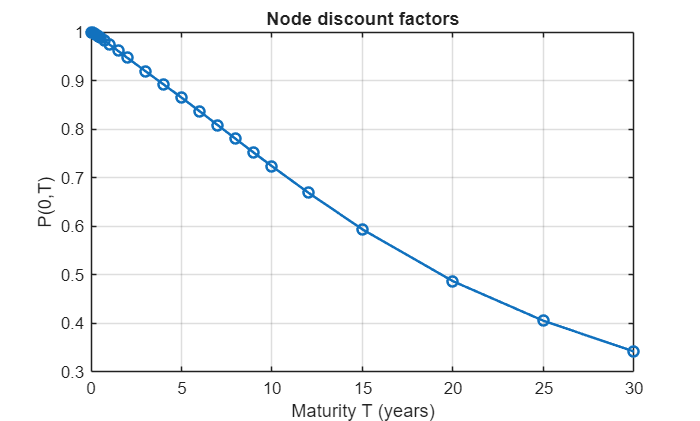


% On visualise les discount factors

figure;
plot(T, P0_nodes, 'o-', 'LineWidth', 1.5);
xlabel('Maturity T (years)');
ylabel('P(0,T)');
title('Node discount factors');
grid on;

## Interpolation de la courbe d’actualisation:

Nous interpolons le logarithme des facteurs d’actualisation $\(\log P(0,T)\)$ à l’aide d’un interpolant cubique hermitien préservant la forme ($\texttt{PCHIP}\$). Ce choix permet de garantir la positivité des facteurs d’actualisation $\(P(0,t)\)$, de produire une structure par terme régulière, et d’éviter les oscillations indésirables souvent observées avec les splines cubiques classiques.

Cette interpolation est utilisée pour obtenir une courbe d’actualisation continue à partir des points nodaux observés. Elle permet notamment d’évaluer $\(P(0,t)\)$ pour des maturités non directement observées, ce qui est nécessaire pour la calibration du modèle de taux et pour la valorisation des produits structurés (c'est le cas aussi avec le Pricing du modèle de Heston avec notre produit lié à un actif).

Par ailleurs, d’après mes connaissances acquises lors de mes cours antérieurs, ainsi que les travaux de mon directeur de thèse et plus généralement la littérature en finance de taux, la structure par terme est très fréquemment modélisée à l’aide de splines ou de méthodes apparentées. L’utilisation d’un interpolant de ce type s’inscrit donc naturellement dans cette famille d’approches, tout en offrant une meilleure stabilité numérique et un comportement plus robuste en pratique.

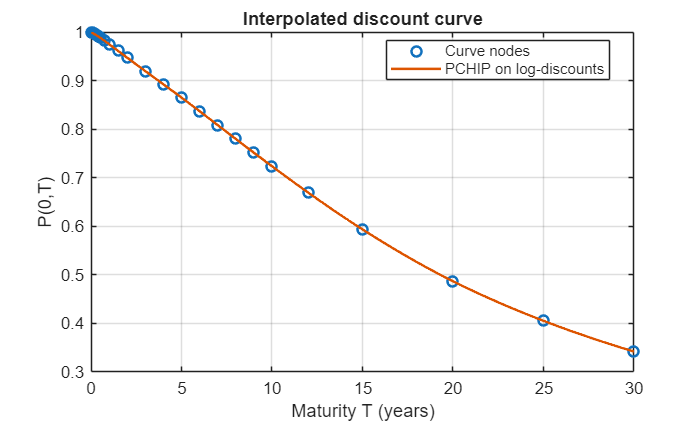

logP_nodes = log(P0_nodes);

logP_interp = @(t) interp1(T, logP_nodes, t, 'pchip', 'extrap');
P_interp = @(t) exp(logP_interp(t));

% Une grid 
tGrid = linspace(min(T), max(T), 1000)';
P0_grid = P_interp(tGrid);


figure;
plot(T, P0_nodes, 'o', 'LineWidth', 1.5); hold on;
plot(tGrid, P0_grid, '-', 'LineWidth', 1.5);
xlabel('Maturity T (years)');
ylabel('P(0,T)');
title('Interpolated discount curve');
legend('Curve nodes', 'PCHIP on log-discounts', 'Location', 'best');
grid on;

% On store tout cela dans un objet MATLAB :)

CurveData = struct();
CurveData.tenorStr = tenorStr;
CurveData.T = T;
CurveData.yPct = yPct;
CurveData.z = z;
CurveData.P0_nodes = P0_nodes;
CurveData.logP_nodes = logP_nodes;
CurveData.logP_interp = logP_interp;
CurveData.P_interp = P_interp;
CurveData.tGrid = tGrid;
CurveData.P0_grid = P0_grid;


## **Taux sans risque pour la calibration du modèle Heston**

Dans le cadre de la calibration du modèle de volatilité stochastique de l’actif, on suppose à ce stade que le taux sans risque est déterministe sur l’horizon considéré. Afin de rester cohérent avec la structure par terme observée au 2 avril 2026, ce taux est extrait de la courbe OIS  précédemment construite et interpolée.

Plus précisément, pour une maturité donnée T (correspondant ici à celle des options utilisées pour la calibration), on récupère le facteur d’actualisation $P(0,T)$ via l’interpolation, puis on en déduit le taux zéro continu équivalent :

     
$$r\left(T\right)=-\frac{\log \left(P\left(0,T\right)\right)}{T}$$


T_call = 0.96098;
P_call = CurveData.P_interp(T_call);
r_call = -log(P_call) / T_call

r_call = 0.0253

## Calibration du **modèle Vasicek sous **$Q$

On cherche à calibrer les paramètres du modèle de Vasicek $\(x = (r_0, \kappa, \theta, \sigma)\$  à partir de la courbe OIS, c.-à-d. des facteurs d’actualisation observés $P_{mkt}(0,T_i).
%$ Sous Vasicek, le prix du zéro-coupon est donné par : 

                                                $
 \[
 P_{\mathrm{model}}(0,T) = A(0,T)\, \exp\bigl(-B(0,T)\, r_0\bigr)
 \]
$ avec  $$$ \left\{ \begin{array}{ll} B(0,T) = \frac{1 - e^{-\kappa T}}{\kappa} \\ A(0,T) = \exp\left( \left(\theta - \frac{\sigma^2}{2\kappa^2}\right)\bigl(B(0,T) - T\bigr) - \frac{\sigma^2}{4\kappa} B(0,T)^2 \right) \end{array} \right. $$$

L’objectif de calibration consiste à minimiser l’erreur quadratique : $
 \[
 J_{\mathrm{fit}} = \frac{1}{N} \sum_{i=1}^N
 \left( P_{\mathrm{model}}(0,T_i) - P_{\mathrm{mkt}}(0,T_i) \right)^2
 \]
$

Sous le modèle de Vasicek, le taux court $r_t$ suit une dynamique gaussienne, ce qui implique que, pour tout $\(t \geq 0\)$, sa distribution est normale : $\[
r_t \sim \mathcal{N}(m(t), v(t)).
\]$

La moyenne et la variance sont données explicitement par $\[
m(t) = r_0 e^{-\kappa t} + \theta \left(1 - e^{-\kappa t}\right),
\]$ $\[
v(t) = \frac{\sigma^2}{2\kappa}\left(1 - e^{-2\kappa t}\right).
\]$

Cette structure gaussienne confère au modèle une grande tractabilité analytique, notamment pour le calcul des prix obligataires. Toutefois, elle implique également que la loi de $r_t$ est supportée sur $\(\mathbb{R}\)$, ce qui signifie que le modèle autorise des taux négatifs avec une probabilité strictement positive. En particulier, cette probabilité s’écrit $\[
\mathbb{P}(r_t < 0) = \Phi\left(-\frac{m(t)}{\sqrt{v(t)}}\right),
\]$ où $\(\Phi\)$ désigne la fonction de répartition de la loi normale centrée réduite. Cette propriété constitue une limite bien connue du modèle de Vasicek et motive l’introduction d’un terme de pénalité dans la calibration afin de contrôler la fréquence de tels événements.

Afin de contrôler la probabilité de taux négatifs, on introduit une pénalité : $
 \[
 J_{\mathrm{neg}} =
 \frac{1}{M} \sum_{j=1}^M
 \left(
 \max\left(
 \Phi\left(-\frac{m(t_j)}{\sqrt{v(t_j)}}\right) - \varepsilon,\ 0
 \right)
 \right)^2
 \]
$. La fonction objectif totale est donc: $
 \[
 J = J_{\mathrm{fit}} + \lambda\, J_{\mathrm{neg}}
 \]
$

Le paramètre $\lambda$ contrôle le compromis entre qualité d’ajustement et plausibilité économique. Dans cette implémentation,  $\lambda$ est choisi via une analyse de sensibilité en testant : $\lambda \in \{20,\ 8,\ 2,\ 0.2\}$ afin d’obtenir un bon équilibre entre fit et contrôle de la probabilité de taux négatifs.

% Hyperparametres de la calibration
lambda = 8;        % poids de la penalite de negativite
epsNeg = 0.01;       % seuil admissible sur P(r_t < 0)

% Point initial
x0 = [z(1), 0.30, mean(z), 0.01];  % sigma initial plus réaliste (1% = 100 bp)

% Bornes
lb = [0.0000, 0.001, 0.0000, 0.0001];
ub = [0.2000, 2.000, 0.2000, 0.5];  % sigma max à 50% 

% Fonction objectif globale (en espace des taux, en points de base)
obj = @(x) vasicek_objective_yield(x, T, z, lambda, epsNeg);

% Options de l'optimiseur
opts = optimoptions('fmincon', ...
    'Display', 'iter', ...
    'Algorithm', 'sqp', ...
    'MaxFunctionEvaluations', 5000, ...
    'MaxIterations', 1000);

% Calibration
[x_hat, J_hat, exitflag, output] = fmincon(obj, x0, [], [], [], [], lb, ub, [], opts);


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           5    2.242569e+03     0.000e+00     1.000e+00     0.000e+00     4.586e+05  
    1          20    1.195036e+03     0.000e+00     2.825e-02     4.853e-02     3.888e+05  
    2          29    8.727562e+02     0.000e+00     2.401e-01     8.449e-02     2.616e+05  
    3          40    8.260561e+02     0.000e+00     1.176e-01     3.136e-02     4.992e+05  
Objective function returned Inf; trying a new point...
    4          54    7.045089e+02     0.000e+00     4.035e-02     2.223e-02     3.797e+05  
    5          64    6.875126e+02     0.000e+00     1.681e-01     1.396e-01     2.011e+05  
    6          79    5.326835e+02     0.000e+00     2.825e-02     1.243e-02     1.685e+05  
    7          89    2.529279e+02     0.000e+00     1.681e-01     9.453e-02     1.281e+05  
    8          94    1.0731

r0_hat    = x_hat(1);
kappa_hat = x_hat(2);
theta_hat = x_hat(3);
sigma_hat = x_hat(4);
fprintf('r0_hat    = %.8f\n', r0_hat);
fprintf('kappa_hat = %.8f\n', kappa_hat);

r0_hat    = 0.02278776


fprintf('theta_hat = %.8f\n', theta_hat);

kappa_hat = 0.19485749


fprintf('sigma_hat = %.8f\n', sigma_hat);

theta_hat = 0.04355716


fprintf('J_hat     = %.8e\n', J_hat);    

sigma_hat = 0.01945824


save("param_Vasicek_RN.mat", "r0_hat", "kappa_hat", "theta_hat", "sigma_hat");

J_hat     = 2.61039379e+01


#### Qualité d'ajustement

P0_fit = ZC_Vasicek(r0_hat, kappa_hat, theta_hat, sigma_hat, T);
z_fit  = -log(P0_fit) ./ T;  % Taux zero implicites du modèle

% Erreurs en espace prix
RMSE_P = sqrt(mean((P0_fit - P0_nodes).^2))
MAE_P  = mean(abs(P0_fit - P0_nodes))

RMSE_P = 0.0026

MaxAbsErr_P = max(abs(P0_fit - P0_nodes))

MAE_P = 0.0017

MaxAbsErr_P = 0.0076

% Erreurs en espace taux (points de base)
RMSE_y_bp = sqrt(mean(((z_fit - z) * 10000).^2))
MAE_y_bp  = mean(abs(z_fit - z) * 10000)

RMSE_y_bp = 5.1043

MaxAbsErr_y_bp = max(abs(z_fit - z) * 10000)

MAE_y_bp = 4.3494

MaxAbsErr_y_bp = 11.0696

Les erreurs obtenues sont faibles : $RMSE = 5.1043\quad bp$,  $MAE = 4.3494 \quad bp$ et $ erreur\ maximale=11.0696 \quad bp
$ 

Le modèle de Vasicek reproduit donc un bon ajustement global, malgré sa structure gaussienne relativement rigide.

**Analyse d'écart**

On examine les erreurs point par point le long de la courbe. Le tableau suivant présente, pour chaque maturité, les facteurs d’actualisation de marché, ceux du modèle, ainsi que l’erreur associée.

ResultsCurve = table(T, P0_nodes, P0_fit, P0_fit - P0_nodes, ...
    z*10000, z_fit*10000, (z_fit - z)*10000, ...
    'VariableNames', {'Maturity','P0_Market','P0_Model','Error_P', ...
                      'Yield_Market_bp','Yield_Model_bp','Error_y_bp'});
disp(ResultsCurve)


    Maturity    P0_Market    P0_Model      Error_P      Yield_Market_bp    Yield_Model_bp    Error_y_bp
    ________    _________    ________    ___________    _______________    ______________    __________

    0.019178     0.99956     0.99956     -2.0414e-06         227.2             228.26          1.0649  
    0.038356     0.99913     0.99912     -6.3265e-06           227             228.65          1.6509  
    0.083333     0.99811     0.99809     -1.7886e-05         227.4             229.55          2.1504  
     0.16667      0.9962     0.99615     -4.9756e-05         228.2              231.2          2.9968  
        0.25      0.9943      0.9942     -0.00010482         228.6             232.82          4.2172  
     0.33333     0.99234     0.99

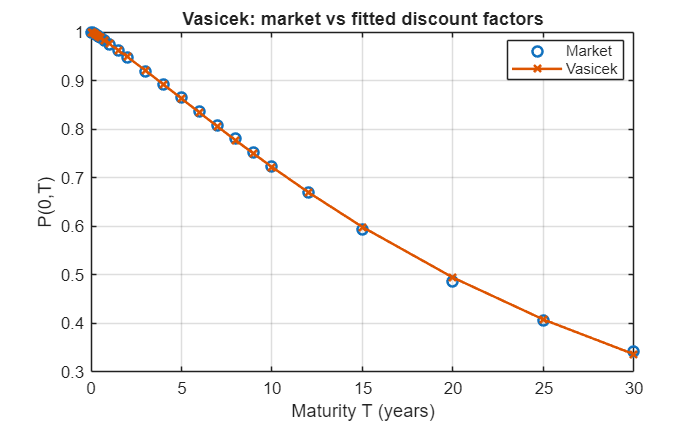

% Figure 1: Facteurs d'actualisation
figure;
plot(T, P0_nodes, 'o', 'LineWidth', 1.5); hold on;
plot(T, P0_fit, 'x-', 'LineWidth', 1.5);
xlabel('Maturity T (years)');
ylabel('P(0,T)');
title('Vasicek: market vs fitted discount factors');
legend('Market','Vasicek','Location','best');
grid on;


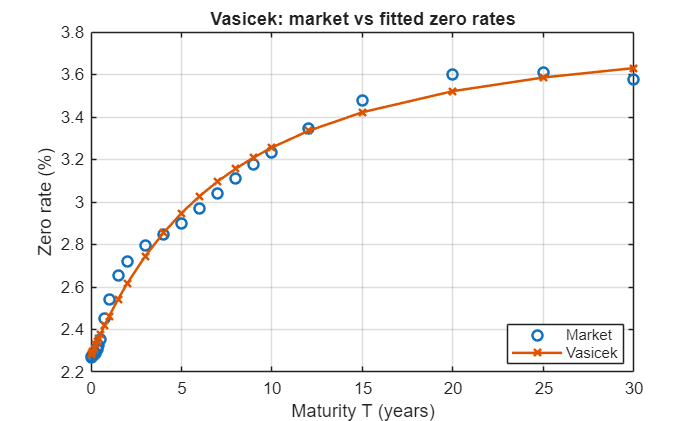

% Figure 2: Taux zero (en %)
figure;
plot(T, z*100, 'o', 'LineWidth', 1.5); hold on;
plot(T, z_fit*100, 'x-', 'LineWidth', 1.5);
xlabel('Maturity T (years)');
ylabel('Zero rate (%)');
title('Vasicek: market vs fitted zero rates');
legend('Market','Vasicek','Location','best');
grid on;


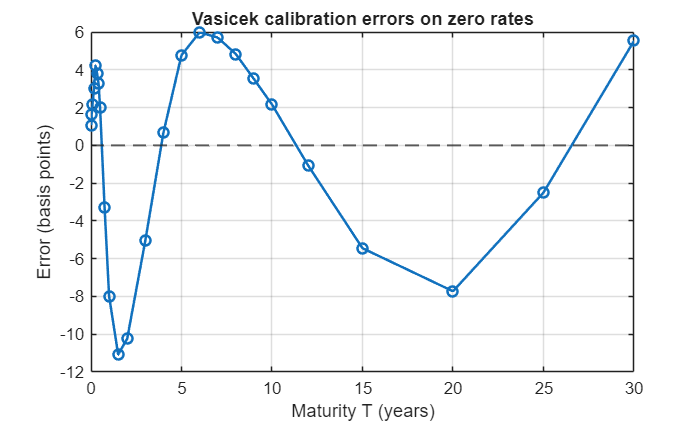

% Figure 3: Erreurs en taux (points de base)
figure;
plot(T, (z_fit - z)*10000, 'o-', 'LineWidth', 1.5);
yline(0, '--', 'LineWidth', 1.2);
xlabel('Maturity T (years)');
ylabel('Error (basis points)');
title('Vasicek calibration errors on zero rates');
grid on;

#### **Fonctions utilisées**

function P0T = ZC_Vasicek(r0, kappa, theta, sigma, T_list)
% Prix zero-coupon sous Vasicek pour plusieurs maturites

    T_list = T_list(:);

    B = (1 - exp(-kappa .* T_list)) ./ kappa;

    A = (theta - sigma^2 / (2 * kappa^2)) .* (B - T_list) ...
      - (sigma^2 ./ (4 * kappa)) .* (B .^ 2);

    P0T = exp(A - B .* r0);
end

function [m, v] = vasicek_mean_var(r0, kappa, theta, sigma, t)
% Moyenne et variance de r_t sous Vasicek

    t = t(:);

    m = r0 .* exp(-kappa .* t) + theta .* (1 - exp(-kappa .* t));
    v = (sigma^2 ./ (2 * kappa)) .* (1 - exp(-2 * kappa .* t));
end

function Jneg = vasicek_negativity_penalty(r0, kappa, theta, sigma, T_monitor, epsNeg)
% Penalite quadratique sur la probabilite de taux negatifs

    [m, v] = vasicek_mean_var(r0, kappa, theta, sigma, T_monitor);
    v = max(v, 1e-14);

    probNeg = normcdf(-m ./ sqrt(v));

    Jneg = mean(max(probNeg - epsNeg, 0).^2);
end

function J = vasicek_objective_yield(x, T_market, y_market, lambda, epsNeg)


    r0    = x(1);
    kappa = x(2);
    theta = x(3);
    sigma = x(4);

    if r0 < 0 || kappa <= 0 || theta < 0 || sigma <= 0
        J = 1e12;
        return;
    end

    % Calcul des taux implicites du modèle
    P0_model = ZC_Vasicek(r0, kappa, theta, sigma, T_market);
    y_model = -log(P0_model) ./ T_market;
    
    % Fit en espace des taux (erreur quadratique moyenne en points de base^2)
    Jfit = mean(((y_model - y_market) * 10000).^2);

    % Penalite de negativite sur une grille de surveillance
    T_monitor = linspace(min(T_market), max(T_market), 200)';
    Jneg = vasicek_negativity_penalty(r0, kappa, theta, sigma, T_monitor, epsNeg);

    
    J = Jfit + lambda * Jneg;
end

## Changement de Mesure

On peut démontrer qu'avec un changement de mesure, on obtient sous un modèle de Vasicek:

                                            
$$\theta^{\mathbb{P}} = \theta^{\mathbb{Q}} + \frac{\sigma\lambda}{\kappa}$$


avec $\sigma$, $\kappa
$ invariant par rapport a ceux sous la mesure $\mathbb{Q}$, sous l'assumption d'une prime de risque constante.

Information utilisée dans cette partie: La loi de transition exacte de Vasicek est Gaussienne. L'estimation par un max likelihood est donc possible et naturelle.

Avec $\sigma$, $\kappa
$ constant, on pourrait démontrer que $\hat{\theta}^{\mathbb{P}}_{MLE}$ coincide with $\hat{\theta}^{\mathbb{P}}_{MSE}$ .

% ici j'ai importe jusqu au 2 Avril (pour consitences des dates dans tout le projet)
CORRAData
CORRAData.Properties.DimensionNames(1) = "date";

CORRAData = 7156×1 timetable
       date        Var2 
    __________    ______

    1997-08-12      3.25
    1997-08-18       3.3
    1997-08-19      3.26
    1997-08-20     3.345
    1997-08-21     3.385
    1997-08-22     3.265
    1997-08-25     3.336
    1997-08-26     3.267
    1997-08-27     3.307
    1997-08-28    3.4615
    1997-09-02    3.4426
    1997-09-03     3.282
    1997-09-04    3.3477
    1997-09-05      3.25
    1997-09-08    3.2702
    1997-09-09     3.289


CORRAData.Properties.DimensionNames(2) = "AVG_INTWO";

dates = datetime(CORRAData.date, 'InputFormat', 'yyyy-MM-dd');
r_raw = CORRAData.AVG_INTWO;

% Conversion en taux decimaux puisque donne en pourcentages
if mean(r_raw, 'omitnan') > 1
    r = r_raw / 100;
else
    r = r_raw;
end

% Tri chronologique
[dates, idx] = sort(dates);
r = r(idx);

% Suppression de doublons eventuels sur les dates
[dates, uniqueIdx] = unique(dates, 'stable');
r = r(uniqueIdx);

length(r)
datetime(dates(1))

ans = 7156

datetime(dates(end))

ans = datetime
   1997-08-12


kappa   = kappa_hat   

ans = datetime
   2026-04-02


sigma   = sigma_hat 

kappa = 0.1949

theta_Q = theta_hat

sigma = 0.0195

theta_Q = 0.0436

Il faut construire les paires $$(r_t,r_{t+1}$)$ et les pas $\Delta_i$ pour les ecarts de dates reels

Delta_vec = days(diff(dates)) / 365; %en unité d'année

r_t  = r(1:end-1);
r_tp = r(2:end);

n = length(r_t)
mean(Delta_vec)

n = 7155

min(Delta_vec)

ans = 0.0040

max(Delta_vec)

ans = 0.0027

ans = 0.0164

On utilise les mêmes formules définis en haut sur le $\mathcal{N}(m(i), v(i)).$

a_vec = exp(-kappa * Delta_vec);
b_vec = 1 - a_vec;
v_vec = (sigma^2 ./ (2 * kappa)) .* (1 - exp(-2 * kappa * Delta_vec));

Dans une exploration initiale, on pose $\Delta_i$  constante $=$ sa moyene pour avoire une valeure representative.

% Alors : %   a = exp(-kappa Delta), b = 1-a et le MLE de theta^P coincide avec les moindres carres.
% Le MLE coincide ici avec les moindres carres CAR la variance conditionnelle est alors constante.
% Ce ne serait pas vrai dans un modele comme CIR ou la variance depend de l'etat r_t, et ou le model suit une loi du xhi^2 non-centrale (Heston)

Delta_bar = mean(Delta_vec)


Delta_bar = 0.0040

a_bar = exp(-kappa * Delta_bar);
b_bar = 1 - a_bar;
v_bar = (sigma^2 / (2 * kappa)) * (1 - exp(-2 * kappa * Delta_bar));

theta_P_closed_constDelta = sum(r_tp - a_bar * r_t) / (n * b_bar)

theta_P_closed_constDelta = 0.0219

### Delta Variable

Ici, on maximise la vraisemblance exacte : $l(\theta^{\mathbb{P}})  = -\frac{1}{2} \sum_{i} \left[ \log(2 \pi v_i) + \frac{(r_{t_{i+1}} - a_i r_{t_i} - b_i \theta^P)^2}{v_i} \right]$

negLogLik_thetaP = @(thetaP) vasicek_negloglik_thetaP_variableDelta( ...
    thetaP, r_t, r_tp, a_vec, b_vec, v_vec);

theta0 = mean(r, 'omitnan');

options = optimset('Display', 'off', 'TolX', 1e-12, 'TolFun', 1e-12, 'MaxIter', 1e5, 'MaxFunEvals', 1e5);
theta_P_mle = fminsearch(negLogLik_thetaP, theta0, options)


theta_P_mle = 0.0219

logLik_hat = -negLogLik_thetaP(theta_P_mle)

logLik_hat = 4.0955e+04

Nous estimons maintenant notre lambda pour bien difinir notre changement de mesure

lambda_hat = (kappa / sigma) * (theta_P_mle - theta_Q) % A chercher reference d un cas similaire et pourquoi!

lambda_hat = -0.2166

Sous le modele exact : $$\text{resid}_i = r_{t_{i+1}} - m_i$ avec $m_i = a_i r_{t_i} + b_i \theta^{\mathbb{P}}$$

Les residus standardisés doivent être approximativement i.i.d. N(0,1) si le modèle est adéquat

mu_hat   = a_vec .* r_t + b_vec .* theta_P_mle;
resid    = r_tp - mu_hat;
z_resid  = resid ./ sqrt(v_vec);

info_thetaP = sum((b_vec .^ 2) ./ v_vec); % information de Fischer observes
var_thetaP  = 1 / info_thetaP;
se_thetaP   = sqrt(var_thetaP)


se_thetaP = 0.0187

IC_low  = theta_P_mle - 1.96 * se_thetaP;
IC_high = theta_P_mle + 1.96 * se_thetaP;
fprintf('IC 95%%= [%.10f , %.10f]\n', IC_low, IC_high);
fprintf('Ecart absolu  de MLE theta avec les deux methodes= %.10e\n', ...

IC 95%= [-0.0146355095 , 0.0584873274]


    abs(theta_P_closed_constDelta - theta_P_mle));

Ecart absolu  de MLE theta avec les deux methodes= 1.2553083988e-05


% Moyenne et variance empiriques
fprintf('Moyenne residus standardises = %.10f\n', mean(z_resid));
fprintf('Variance residus standardises = %.10f\n', var(z_resid, 1));

Moyenne residus standardises = 0.0018479303


[h_lbq, p_lbq] = lbqtest(z_resid, 'Lags', min(10, floor(length(z_resid)/5)))

Variance residus standardises = 0.2491387846


[h_jb, p_jb] = jbtest(z_resid)

h_lbq = logical
   1


p_lbq = 2.2204e-16

h_jb = 1

p_jb = 1.0000e-03

Le test de Jarque-Bera a retourné une p-value de 0,001 avec un avertissement indiquant que la vraie p-value est inférieure à la plus petite valeur tabulée, ce qui signifie que la normalité est fortement rejetée (p < 0,001). Conjointement avec le test de Ljung-Box (p ≈ 0), ces résultats confirment que les hypothèses du modèle de Vasicek d'erreurs gaussiennes indépendantes sont violées par les données. Ce qui nous donne aussi une idée sur certains limitations de Vasicek.

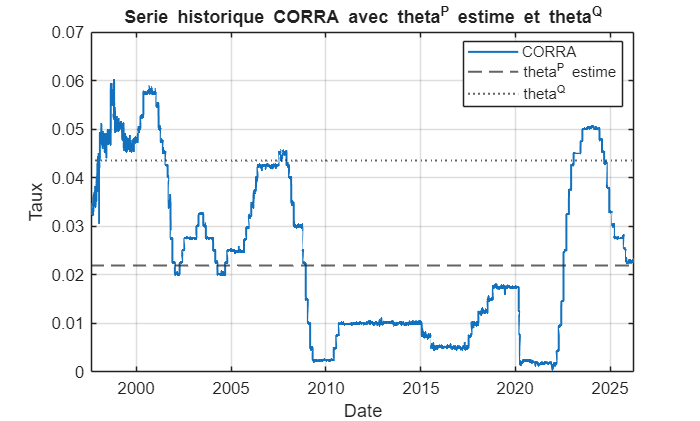

figure;
plot(dates, r, 'LineWidth', 1.2); hold on;
yline(theta_P_mle, '--', 'LineWidth', 1.2);
yline(theta_Q, ':', 'LineWidth', 1.2);
grid on;
xlabel('Date');
ylabel('Taux');
title('Serie historique CORRA avec theta^P estime et theta^Q');
legend('CORRA', 'theta^P estime', 'theta^Q', 'Location', 'best');
figure;

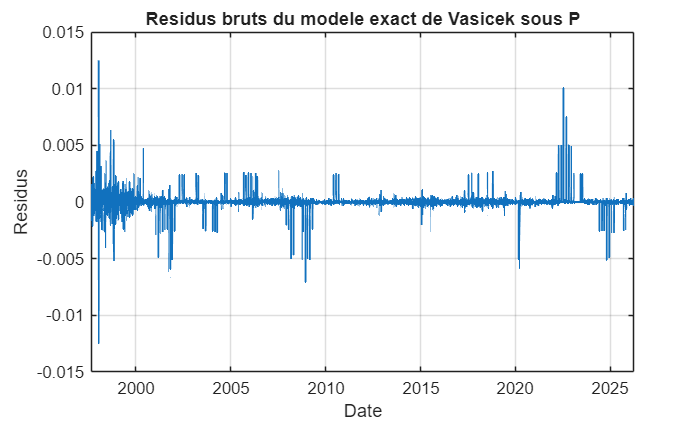

plot(dates(2:end), resid, 'LineWidth', 1.1);
grid on;
xlabel('Date');
ylabel('Residus');
title('Residus bruts du modele exact de Vasicek sous P');
figure;

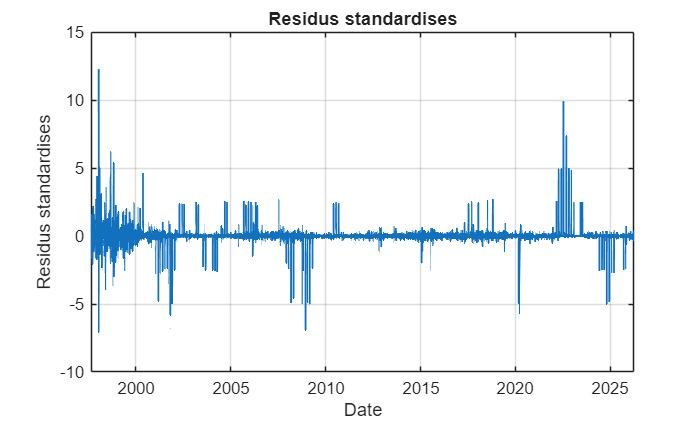

plot(dates(2:end), z_resid, 'LineWidth', 1.1);
grid on;
xlabel('Date');
ylabel('Residus standardises');
title('Residus standardises');
figure;

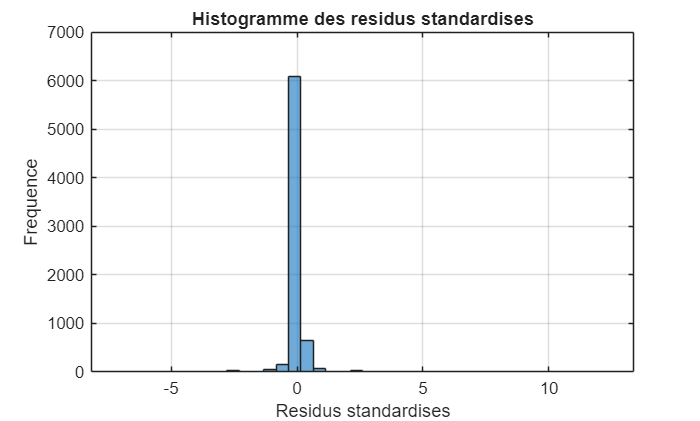

histogram(z_resid, 40);
grid on;
xlabel('Residus standardises');
ylabel('Frequence');
title('Histogramme des residus standardises');

### Fonction locale

function nll = vasicek_negloglik_thetaP_variableDelta(thetaP, r_t, r_tp, a_vec, b_vec, v_vec)

    mu = a_vec .* r_t + b_vec .* thetaP;
    resid = r_tp - mu;

    nll = 0.5 * sum(log(2 * pi * v_vec) + (resid .^ 2) ./ v_vec);

end

## Produit sur taux d'intérêt 1: Note à coupon inverse sur taux court moyen

Le produit taux considéré dans cette section est une note à capital protégé versant des coupons trimestriels dont le niveau dépend inversement du taux court observé sur chaque trimestre. L'objectif est de construire un produit cohérent avec le besoin du client, à savoir des revenus réguliers plus élevés lorsque les taux d'intérêt demeurent faibles, et des revenus plus modestes lorsque les taux montent.

La maturité du produit est fixée à deux ans, avec huit dates d'observation et de paiement trimestrielles. Pour calculer les taux moyens trimestriels, on simule les trajectoires du taux court sur une grille journalière de $252$ pas par année.

rng(12345, 'twister');   % reproductibilite

T_prod = 2;          % maturite en annees
M      = 8;          % coupons trimestriels
N      = 100000;      % nombre de trajectoires
nSteps = 365*T_prod; % discretisation journaliere
dt     = T_prod / nSteps;
N0     = 1000;       % nominal

t_trim      = (1:M)' / 4;
temps_obs = round(t_trim / dt);
disc_factor = CurveData.P_interp(t_trim);
P0_Tprod    = CurveData.P_interp(T_prod);

Dans le code, la simulation est effectuée à l'aide d'un schéma d'Euler discret : $\[
r_{t+\Delta t} = r_t + \kappa(\theta-r_t)\Delta t + \sigma \sqrt{\Delta t}\, Z_t,
\qquad Z_t \sim \mathcal N(0,1).
\]$

A partir des trajectoires simulées, on calcule pour chaque trimestre $q\;$le taux moyen observé sur la sous-période, noté $\(\bar r_q\)$

function [r_paths, r_avg] = simulate_vasicek_Q(r0, kappa, theta, sigma, dt, nSteps, N, temps_obs)

    M = length(temps_obs);

    r_paths = zeros(nSteps+1, N);
    r_paths(1,:) = r0;

    for t = 1:nSteps
        Z = randn(1, N);
        r_paths(t+1,:) = r_paths(t,:) ...
            + kappa * (theta - r_paths(t,:)) * dt ...
            + sigma * sqrt(dt) .* Z;
    end

    r_avg = zeros(M, N);
    idx_prev = 0;

    for q = 1:M
        idx_q = temps_obs(q);

        % moyenne du taux sur la sous-periode
        r_avg(q,:) = mean(r_paths(idx_prev+1:idx_q, :), 1);

        idx_prev = idx_q;
    end
end

Le coupon trimestriel annualisé est construit de manière à intégrer un coupon de base, une exposition inverse au niveau moyen du taux, ainsi qu'un mécanisme de protection par floor et cap. Plus précisément, pour chaque trimestre $q$, on pose $\[
C_q
=
\max\!\left(
C_{\min},
\min\!\left(
C_{\max},
c_0 + \beta (K-\bar r_q)
\right)\right).
\]$

Ici :

-      $\(c_0\)$ représente le coupon de base,

-      $\(\beta\)$ mesure la sensibilité inverse aux taux,

-     $\(K\)$ est le niveau de référence du taux,

-     $ \(C_{\min}\)$ et $\(C_{\max}\)$ encadrent les paiements.

Le coupon payé sur le trimestre est alors $\[
\text{Coupon}_q = N_0\, C_q\, \Delta,
\qquad \Delta=\frac14.
\]$

function coupons = compute_coupons_ir(r_avg, c0, beta, K, Cmin, Cmax)

    coupons = c0 + beta * (K - r_avg);
    coupons = max(Cmin, min(Cmax, coupons));

end

La valeur initiale du produit est obtenue comme la somme de deux composantes :

la valeur actualisée du remboursement du nominal à maturité, et la valeur actualisée de la jambe de coupons trimestriels.

function V0 = price_product_ir_Q(r_paths_Q, r_avg_Q, c0, beta, K, Cmin, Cmax, ...
                                 dt, temps_obs, N0, M, T_prod)

    Delta = T_prod / M;

    coupons = compute_coupons_ir(r_avg_Q, c0, beta, K, Cmin, Cmax);
    disc_paths = exp(-cumsum(r_paths_Q(1:end-1,:) * dt, 1)); % factuer d actu

    % Facteurs aux dates de paiement trimestrielles
    disc_pay = disc_paths(temps_obs, :);
    coupon_leg_paths = N0 * Delta * sum(disc_pay .* coupons, 1);
    capital_paths = N0 * disc_pay(end, :);
    V0 = mean(capital_paths + coupon_leg_paths); %V0 initial
end

Dans cette structure, les paramètres$ \(c_0\), \(K\), \(C_{\min}\)$ et $\(C_{\max}\)$ sont fixés au préalable afin de définir le profil économique du produit. Le coefficient $\beta$ joue alors le rôle de paramètre ajustable, choisi pour maintenir la condition d'équité. Comme la présence du floor et du cap brise l'affinité du prix en $\beta$, il est plus simple ici d'obtenir $\(\beta^\star\)$ par une recherche numérique.

function beta_star = solve_fair_beta_ir(r_paths_Q, r_avg_Q, c0, K, Cmin, Cmax, ...
                                        dt, temps_obs, N0, M, T_prod)

    obj = @(beta) price_product_ir_Q(r_paths_Q, r_avg_Q, c0, beta, K, Cmin, Cmax, ...
                                     dt, temps_obs, N0, M, T_prod) - N0;

    beta_low  = 0.0;
    beta_high = 50.0;

    f_low  = obj(beta_low);
    f_high = obj(beta_high);

    while f_low * f_high > 0
        beta_high = 2 * beta_high;
        f_high = obj(beta_high);

        if beta_high > 1e5
            beta_star = NaN;
            return;
        end
    end

    beta_star = fzero(obj, [beta_low, beta_high]);
end

On simule sous $Q$ :

[r_Q, r_avg_Q] = simulate_vasicek_Q(r0_hat, kappa_hat, theta_hat, sigma_hat, ...
                                    dt, nSteps, N, temps_obs);

### Choix des profils

Choix des deux configurations:

        I. La première configuration est dite conservatrice. Elle privilégie un coupon de base relativement élevé, une sensibilité inverse modérée, ainsi qu'un encadrement plus resserré des coupons. Elle s'adresse à un investisseur recherchant des revenus plus stables, tout en profitant modérément des régimes de taux bas.

        II. La seconde configuration est dite dynamique. Elle repose sur un coupon de base plus faible, mais autorise une sensibilité plus importante via $\beta$, ainsi qu'un plafond de coupon plus élevé. Elle convient davantage à un investisseur acceptant une plus grande variabilité des paiements en échange d'une meilleure participation aux scénarios de baisse des taux.

#### 1. Profil conservateur

Nos résultats de calibration peuvent nous transmettre une idée que le taux court part d’un niveau initial $\(r_0 = 2.27\%\)$ et converge vers un niveau de long terme $ \(\theta = 3.87\%\)$. Sur l’horizon considéré, il est donc naturel de sélectionner un niveau de référence $K$ compris entre ces deux valeurs, de manière à refléter un niveau plausible des taux moyens futurs tout en évitant une structure excessivement favorable ou défavorable.

rng(12345, 'twister'); 
c0_1   = 0.017;
K_1    = (r0_hat+theta_hat)/2

K_1 = 0.0332

Cmin_1 = 0.01;
Cmax_1 = 0.040;

beta_1 = solve_fair_beta_ir(r_Q, r_avg_Q, c0_1, K_1, Cmin_1, Cmax_1, ...
                            dt, temps_obs, N0, M, T_prod);

V0_1 = price_product_ir_Q(r_Q, r_avg_Q, c0_1, beta_1, K_1, Cmin_1, Cmax_1, ...
                          dt, temps_obs, N0, M, T_prod);
fprintf('beta_1 = %.8f\n', beta_1);

beta_1 = 1.36312101


fprintf('V0_1   = %.8f\n', V0_1);

V0_1   = 1000.00000000


#### 2. Profil dynamique

c0_2   = 0.012;
K_2    = K_1;
Cmin_2 = 0.000;
Cmax_2 = 0.065;

beta_2 = solve_fair_beta_ir(r_Q, r_avg_Q, c0_2, K_2, Cmin_2, Cmax_2, ...
                            dt, temps_obs, N0, M, T_prod);

V0_2 = price_product_ir_Q(r_Q, r_avg_Q, c0_2, beta_2, K_2, Cmin_2, Cmax_2, ...
                          dt, temps_obs, N0, M, T_prod);

fprintf('beta_2 = %.8f\n', beta_2);

beta_2 = 1.68499560


fprintf('V0_2   = %.8f\n', V0_2);

V0_2   = 1000.00000000


Afin de comparer les deux configurations au-delà de la seule condition d'équité, on analyse la distribution des coupons simulés sous $Q$. On calcule notamment la moyenne ainsi que certains quantiles empiriques des coupons annualisés.

### Statistiques des coupons sous Q

C1_Q = compute_coupons_ir(r_avg_Q, c0_1, beta_1, K_1, Cmin_1, Cmax_1);
C2_Q = compute_coupons_ir(r_avg_Q, c0_2, beta_2, K_2, Cmin_2, Cmax_2);
fprintf('\nConfiguration 1 :\n');


Configuration 1 :


disp(quantile(C1_Q(:), [0.1 0.5 0.9]))

    0.0100    0.0274    0.0400



disp(mean(C1_Q(:)))

    0.0261



fprintf('\nConfiguration 2 :\n');


Configuration 2 :


disp(quantile(C2_Q(:), [0.1 0.5 0.9]))

         0    0.0249    0.0575



disp(mean(C2_Q(:)))

    0.0260



Les deux configurations présentent une valeur moyenne de coupons identiques. En revanche, la dispersion des coupons est plus forte dans la seconde configuration, car celle-ci dépend davantage de la composante variable liée au niveau moyen des taux.

### Statistiques des coupons sous Q

On réalise maintenant une analyse de sensibilité sur les paramètres libres du produit. Comme pour le produit actions, on distingue :

        I. une sensibilité avec recalibration de $\(\beta^\star\)$,

        II. une sensibilité brute de $\(V_0\)$ en fonction du paramètre libre choisi.

On fait ceci sur les deux configurations

#### Sur la configuration 1

- a. Sensibilité de K avec recalibration de $\beta^\star\$

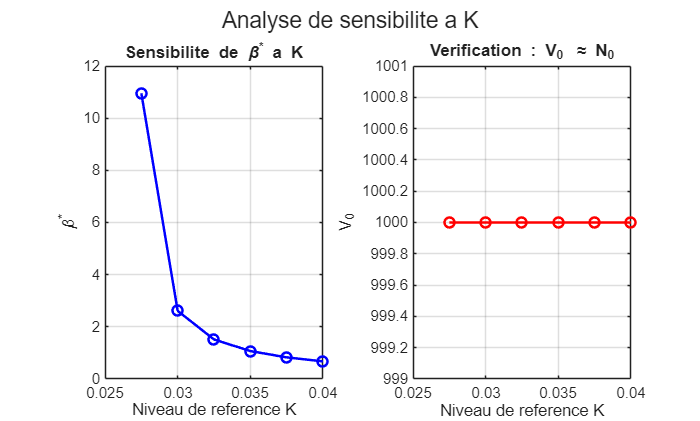

% Sensibilite 1 : impact de K sur beta* (Config 1) - pour que ca reste equitable
K_range = 0.015 : 0.0025 : 0.040;
beta_K  = zeros(size(K_range));
V0_K    = zeros(size(K_range));

for i = 1:length(K_range)
    K_i = K_range(i);

    beta_i   = solve_fair_beta_ir(r_Q, r_avg_Q, c0_1, K_i, Cmin_1, Cmax_1, ...
                                 dt, temps_obs, N0, M, T_prod);
    beta_K(i) = beta_i;

    if isnan(beta_i)
        V0_K(i) = NaN;
    else
        V0_K(i) = price_product_ir_Q(r_Q, r_avg_Q, c0_1, beta_i, K_i, Cmin_1, Cmax_1, ...
                                     dt, temps_obs, N0, M, T_prod);
    end
end

figure;
subplot(1,2,1);
plot(K_range, beta_K, 'b-o', 'LineWidth', 1.5);
xlabel('Niveau de reference K');
ylabel('\beta^*');
title('Sensibilite de \beta^* a K');
grid on;

subplot(1,2,2);
plot(K_range, V0_K, 'r-o', 'LineWidth', 1.5);
xlabel('Niveau de reference K');
ylabel('V_0');
title('Verification : V_0 \approx N_0');
grid on;

sgtitle('Analyse de sensibilite a K');

- b. Sensibilité de $$c_0$$ avec recalibration de $\beta^\star\$

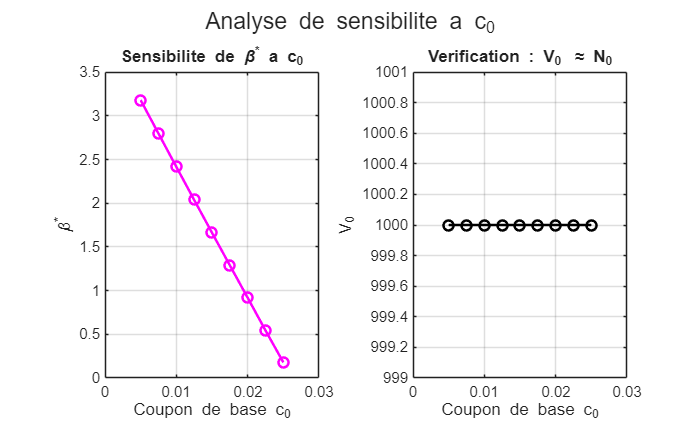

c0_range = 0.005 : 0.0025 : 0.04;
beta_c0  = zeros(size(c0_range));
V0_c0    = zeros(size(c0_range));

for i = 1:length(c0_range)
    c0_i = c0_range(i);

    beta_i    = solve_fair_beta_ir(r_Q, r_avg_Q, c0_i, K_1, Cmin_1, Cmax_1, ...
                                   dt, temps_obs, N0, M, T_prod);
    beta_c0(i) = beta_i;

    if isnan(beta_i)
        V0_c0(i) = NaN;
    else
        V0_c0(i) = price_product_ir_Q(r_Q, r_avg_Q, c0_i, beta_i, K_1, Cmin_1, Cmax_1, ...
                                      dt, temps_obs, N0, M, T_prod);
    end
end

figure;
subplot(1,2,1);
plot(c0_range, beta_c0, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon de base c_0');
ylabel('\beta^*');
title('Sensibilite de \beta^* a c_0');
grid on;

subplot(1,2,2);
plot(c0_range, V0_c0, 'k-o', 'LineWidth', 1.5);
xlabel('Coupon de base c_0');
ylabel('V_0');
title('Verification : V_0 \approx N_0');
grid on;

sgtitle('Analyse de sensibilite a c_0');

            1. c. Analyse de sensibilite brute de K

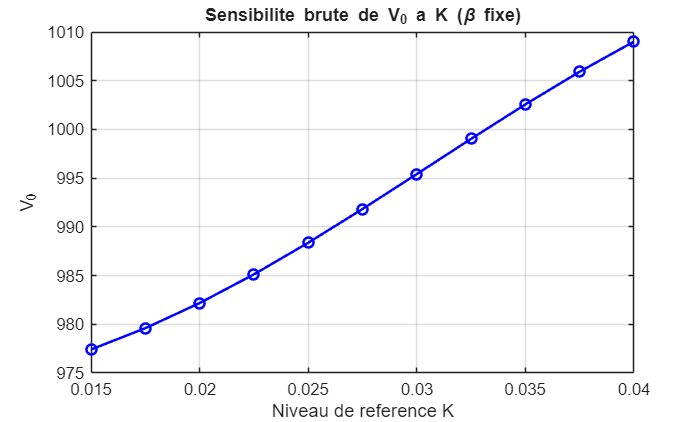

K_range_brut = 0.015 : 0.0025 : 0.040;
V0_K_brut    = zeros(size(K_range_brut));

for i = 1:length(K_range_brut)
    K_i = K_range_brut(i);

    V0_K_brut(i) = price_product_ir_Q(r_Q, r_avg_Q, c0_1, beta_1, K_i, Cmin_1, Cmax_1, ...
                                      dt, temps_obs, N0, M, T_prod);
end

figure;
plot(K_range_brut, V0_K_brut, 'b-o', 'LineWidth', 1.5);
xlabel('Niveau de reference K');
ylabel('V_0');
title('Sensibilite brute de V_0 a K (\beta fixe)');
grid on;

- d. Analyse de sensibilite brute de $$c_0$$

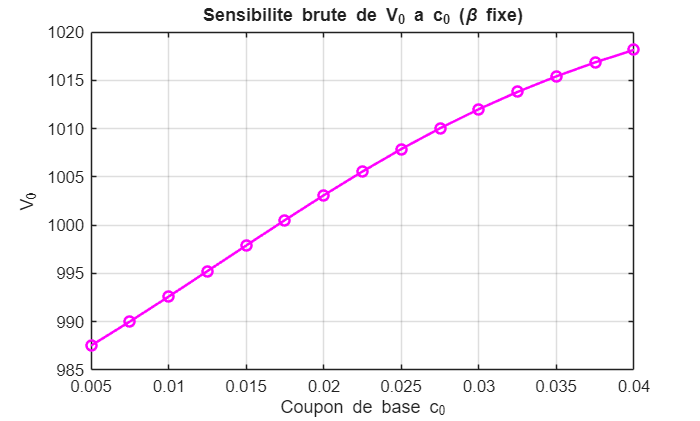

c0_range_brut = 0.005 : 0.0025 : 0.04;
V0_c0_brut    = zeros(size(c0_range_brut));

for i = 1:length(c0_range_brut)
    c0_i = c0_range_brut(i);

    V0_c0_brut(i) = price_product_ir_Q(r_Q, r_avg_Q, c0_i, beta_1, K_1, Cmin_1, Cmax_1, ...
                                       dt, temps_obs, N0, M, T_prod);
end

figure;
plot(c0_range_brut, V0_c0_brut, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon de base c_0');
ylabel('V_0');
title('Sensibilite brute de V_0 a c_0 (\beta fixe)');
grid on;

#### Sur la configuration 2

            2. a. Recalibration de $\beta^\star\$

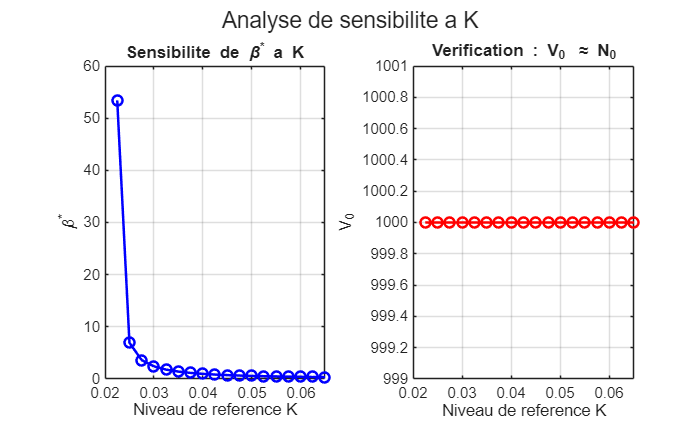

K_range = 0.015 : 0.0025 : 0.065;
beta_K  = zeros(size(K_range));
V0_K    = zeros(size(K_range));

for i = 1:length(K_range)
    K_i = K_range(i);

    beta_i   = solve_fair_beta_ir(r_Q, r_avg_Q, c0_2, K_i, Cmin_2, Cmax_2, ...
                                  dt, temps_obs, N0, M, T_prod);
    beta_K(i) = beta_i;

    if isnan(beta_i)
        V0_K(i) = NaN;
    else
        V0_K(i) = price_product_ir_Q(r_Q,  r_avg_Q, c0_2, beta_i, K_i, Cmin_2, Cmax_2, ...
                                     dt, temps_obs, N0, M, T_prod);
    end
end

figure;
subplot(1,2,1);
plot(K_range, beta_K, 'b-o', 'LineWidth', 1.5);
xlabel('Niveau de reference K');
ylabel('\beta^*');
title('Sensibilite de \beta^* a K');
grid on;

subplot(1,2,2);
plot(K_range, V0_K, 'r-o', 'LineWidth', 1.5);
xlabel('Niveau de reference K');
ylabel('V_0');
title('Verification : V_0 \approx N_0');
grid on;

sgtitle('Analyse de sensibilite a K');

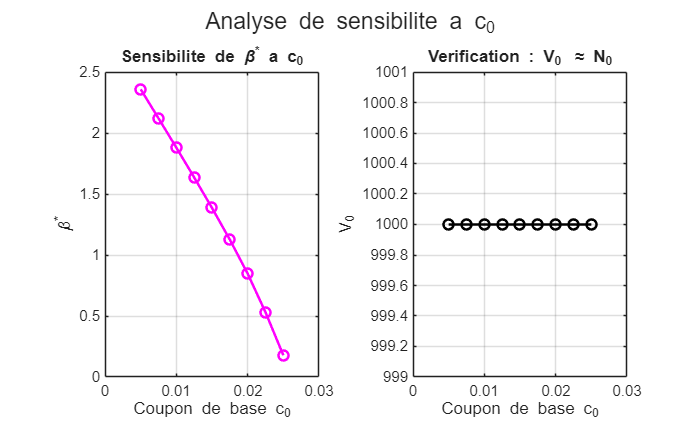

c0_range = 0.005 : 0.0025 : 0.035;
beta_c0  = zeros(size(c0_range));
V0_c0    = zeros(size(c0_range));

for i = 1:length(c0_range)
    c0_i = c0_range(i);

    beta_i    = solve_fair_beta_ir(r_Q, r_avg_Q, c0_i, K_2, Cmin_2, Cmax_2, ...
                                   dt, temps_obs, N0, M, T_prod);
    beta_c0(i) = beta_i;

    if isnan(beta_i)
        V0_c0(i) = NaN;
    else
        V0_c0(i) = price_product_ir_Q(r_Q, r_avg_Q, c0_i, beta_i, K_2, Cmin_2, Cmax_2, ...
                                      dt, temps_obs, N0, M, T_prod);
    end
end

figure;
subplot(1,2,1);
plot(c0_range, beta_c0, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon de base c_0');
ylabel('\beta^*');
title('Sensibilite de \beta^* a c_0');
grid on;

subplot(1,2,2);
plot(c0_range, V0_c0, 'k-o', 'LineWidth', 1.5);
xlabel('Coupon de base c_0');
ylabel('V_0');
title('Verification : V_0 \approx N_0');
grid on;

sgtitle('Analyse de sensibilite a c_0');

            2. b. Analyse de sensibilite brute

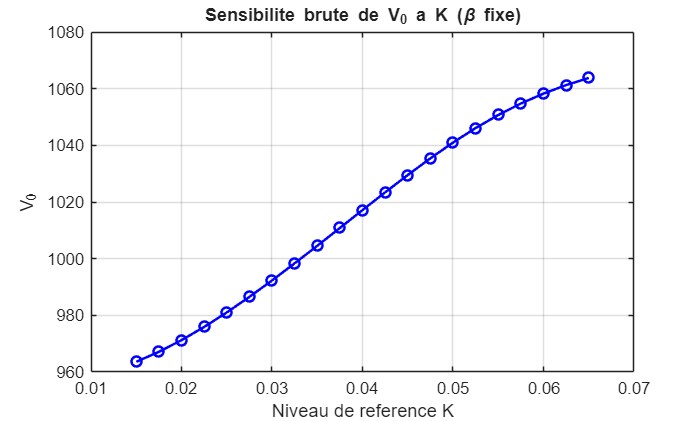

K_range_brut = 0.015 : 0.0025 : 0.065;
V0_K_brut    = zeros(size(K_range_brut));

for i = 1:length(K_range_brut)
    K_i = K_range_brut(i);

    V0_K_brut(i) = price_product_ir_Q(r_Q, r_avg_Q, c0_2, beta_2, K_i, Cmin_2, Cmax_2, ...
                                      dt, temps_obs, N0, M, T_prod);
end

figure;
plot(K_range_brut, V0_K_brut, 'b-o', 'LineWidth', 1.5);
xlabel('Niveau de reference K');
ylabel('V_0');
title('Sensibilite brute de V_0 a K (\beta fixe)');
grid on;

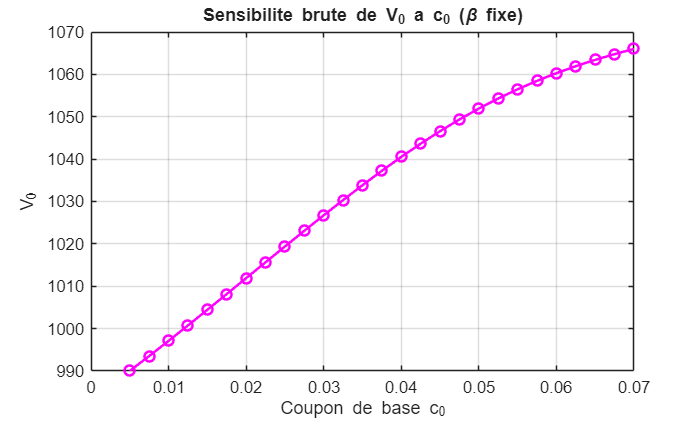

c0_range_brut = 0.005 : 0.0025 : 0.07;
V0_c0_brut    = zeros(size(c0_range_brut));

for i = 1:length(c0_range_brut)
    c0_i = c0_range_brut(i);

    V0_c0_brut(i) = price_product_ir_Q(r_Q, r_avg_Q, c0_i, beta_2, K_2, Cmin_2, Cmax_2, ...
                                       dt, temps_obs, N0, M, T_prod);
end

figure;
plot(c0_range_brut, V0_c0_brut, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon de base c_0');
ylabel('V_0');
title('Sensibilite brute de V_0 a c_0 (\beta fixe)');
grid on;

### Simulation sous $\mathbb{P}
$

Sous la mesure historique $\mathbb{P}
$, on s’intéresse aux gains réalisés par l’investisseur. On ignore l’actualisation (cadre de pricing sous $\mathbb{Q}
$) et on regarde simplement le cashflow total reçu, i.e. un rendement brut sur l’horizon.

rng(12345, 'twister'); 
r0 =  r(end) % 2 avril valeur

r0 = 0.0227

[r_P, r_avg_P] = simulate_vasicek_Q(r0, kappa_hat, theta_P_mle, sigma_hat, ...
                                     dt, nSteps, N, temps_obs);

% Config 1 — Conservatrice
C1_P = compute_coupons_ir(r_avg_P, c0_1, beta_1, K_1, Cmin_1, Cmax_1);

% Config 2 — Dynamique
C2_P = compute_coupons_ir(r_avg_P, c0_2, beta_2, K_2, Cmin_2, Cmax_2);


Pour la valeur totale du produit sous P (rendement total actualisé) On calcule le payoff total actualisé par trajectoire pour avoir  une distribution de "valeur de marché" sous P

Delta = T_prod / M;   % = 0.25 (trimestriel)

% Cashflows totaux non actualisés par trajectoire
coupon_total_1_P = N0 * Delta * sum(C1_P, 1);  % somme des coupons
coupon_total_2_P = N0 * Delta * sum(C2_P, 1);

CF_total_1_P = N0 + coupon_total_1_P;   % nominal + coupons
CF_total_2_P = N0 + coupon_total_2_P;

% Rendement total (en %) par rapport au nominal
rendement_1_P = (CF_total_1_P - N0) / N0 * 100;
rendement_2_P = (CF_total_2_P - N0) / N0 * 100;


fprintf('  Moyenne rendement (Conf 1): %.4f%%\n', mean(rendement_1_P));

  Moyenne rendement (Conf 1): 5.6861%


fprintf('  Std rendement (Conf 1): %.4f%%\n', std(rendement_1_P));

  Std rendement (Conf 1): 1.8373%


disp('  Quantiles [10%, 50%, 90%] (Conf 1):');

  Quantiles [10%, 50%, 90%] (Conf 1):


disp(quantile(rendement_1_P, [0.10 0.50 0.90]))

    2.9020    6.0202    7.8718



fprintf('  Moyenne rendement  (Conf 2): %.4f%%\n', mean(rendement_2_P));

  Moyenne rendement  (Conf 2): 6.0810%


fprintf('  Std rendement     (Conf 2): %.4f%%\n', std(rendement_2_P));

  Std rendement     (Conf 2): 3.4289%


disp('  Quantiles [10%, 50%, 90%] (Conf 2):');

  Quantiles [10%, 50%, 90%] (Conf 2):


disp(quantile(rendement_2_P, [0.10 0.50 0.90]))

    1.4449    5.9704   10.9280



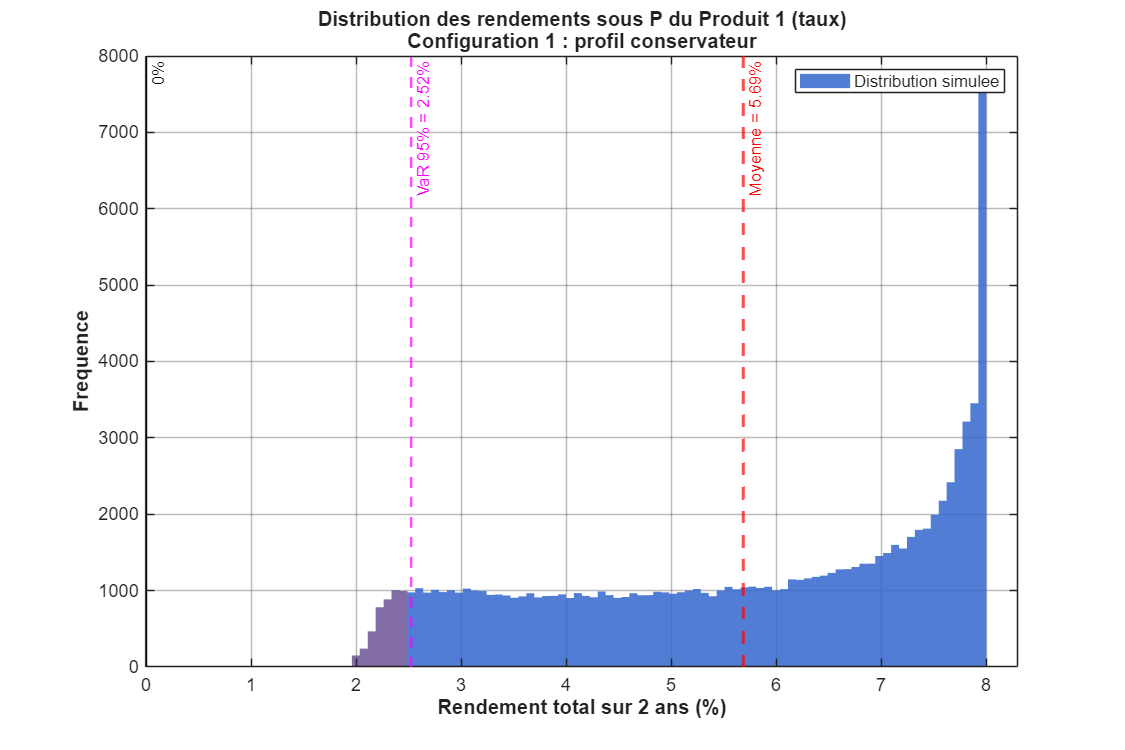

figure('Name', 'Configuration conservatrice - Distribution sous P', ...
       'Position', [100, 100, 900, 600]);

mu_1     = mean(rendement_1_P);
VaR_95_1 = prctile(rendement_1_P, 5);

h1 = histogram(rendement_1_P, 80, ...
    'FaceColor', [0.2 0.4 0.8], ...
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.85);
hold on;

% Zone VaR (queue gauche)
binEdges_1   = h1.BinEdges;
binCounts_1  = h1.Values;
binCenters_1 = (binEdges_1(1:end-1) + binEdges_1(2:end)) / 2;
maskVaR_1    = binCenters_1 <= VaR_95_1;

bar(binCenters_1(maskVaR_1), binCounts_1(maskVaR_1), ...
    1.0, ...
    'FaceColor', [0.85 0.3 0.3], ...
    'FaceAlpha', 0.35, ...
    'EdgeColor', 'none');

xline(mu_1, '--r', ...
    ['Moyenne = ' num2str(mu_1, '%.2f') '%'], ...
    'LineWidth', 1.8);

xline(0, '-k', ...
    '0%', ...
    'LineWidth', 1.3);

xline(VaR_95_1, '--m', ...
    ['VaR 95% = ' num2str(VaR_95_1, '%.2f') '%'], ...
    'LineWidth', 1.5);

xlabel('Rendement total sur 2 ans (%)', ...
    'FontSize', 12, 'FontWeight', 'bold');
ylabel('Frequence', ...
    'FontSize', 12, 'FontWeight', 'bold');

title({'Distribution des rendements sous P du Produit 1 (taux)', ...
       'Configuration 1 : profil conservateur'}, ...
      'FontSize', 14, ...
      'FontWeight', 'bold', ...
      'Interpreter', 'none');

legend(h1, 'Distribution simulee', ...
    'Location', 'northeast', ...
    'FontSize', 10);

grid on;
box on;

ax = gca;
ax.FontSize = 11;
ax.GridAlpha = 0.3;

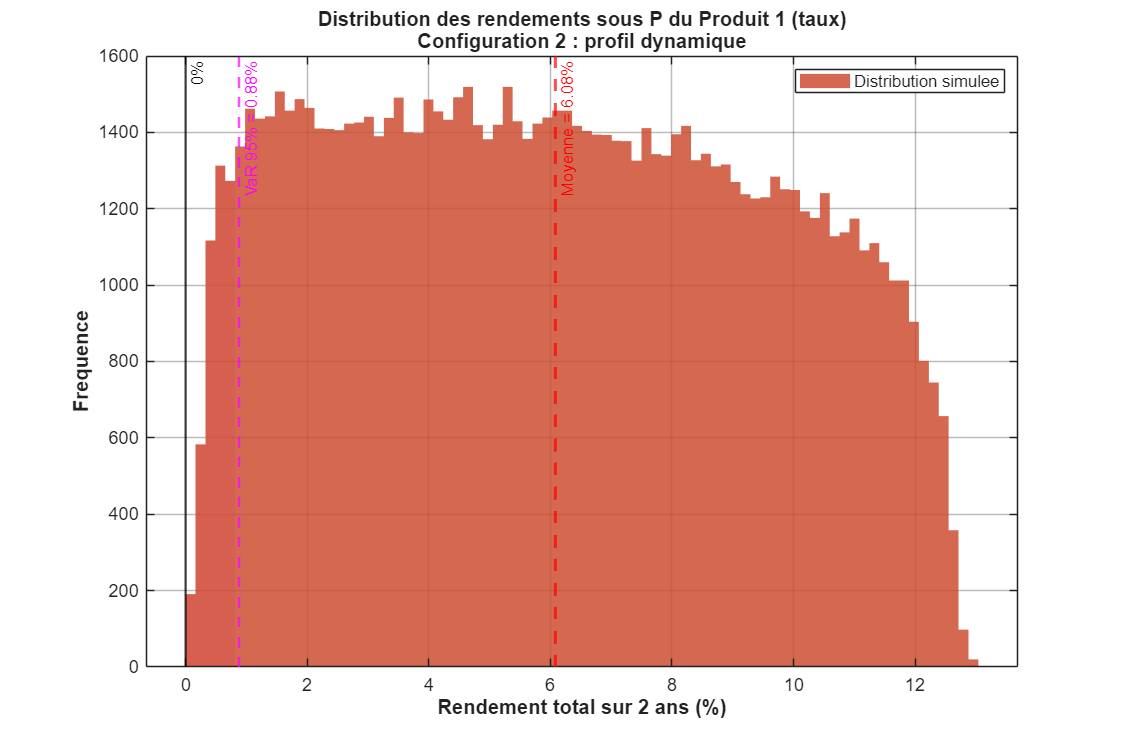

% Conf 2

figure('Name', 'Configuration dynamique - Distribution sous P', ...
       'Position', [150, 150, 900, 600]);

mu_2     = mean(rendement_2_P);
VaR_95_2 = prctile(rendement_2_P, 5);

h2 = histogram(rendement_2_P, 80, ...
    'FaceColor', [0.8 0.3 0.2], ...
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.85);
hold on;

binEdges_2   = h2.BinEdges;
binCounts_2  = h2.Values;
binCenters_2 = (binEdges_2(1:end-1) + binEdges_2(2:end)) / 2;
maskVaR_2    = binCenters_2 <= VaR_95_2;

bar(binCenters_2(maskVaR_2), binCounts_2(maskVaR_2), ...
    1.0, ...
    'FaceColor', [0.85 0.3 0.3], ...
    'FaceAlpha', 0.35, ...
    'EdgeColor', 'none');

xline(mu_2, '--r', ...
    ['Moyenne = ' num2str(mu_2, '%.2f') '%'], ...
    'LineWidth', 1.8);

xline(0, '-k', ...
    '0%', ...
    'LineWidth', 1.3);

xline(VaR_95_2, '--m', ...
    ['VaR 95% = ' num2str(VaR_95_2, '%.2f') '%'], ...
    'LineWidth', 1.5);

xlabel('Rendement total sur 2 ans (%)', ...
    'FontSize', 12, 'FontWeight', 'bold');
ylabel('Frequence', ...
    'FontSize', 12, 'FontWeight', 'bold');

title({'Distribution des rendements sous P du Produit 1 (taux)', ...
       'Configuration 2 : profil dynamique'}, ...
      'FontSize', 14, ...
      'FontWeight', 'bold', ...
      'Interpreter', 'none');

legend(h2, 'Distribution simulee', ...
    'Location', 'northeast', ...
    'FontSize', 10);

grid on;
box on;

ax = gca;
ax.FontSize = 11;
ax.GridAlpha = 0.3;

alpha = 0.05;  % Niveau de confiance 95% (pertes dans les 5% pires cas)

VaR_95_1 = prctile(rendement_1_P, alpha * 100)

VaR_95_1 = 2.5246

ES_95_1  = mean(rendement_1_P(rendement_1_P <= VaR_95_1))

ES_95_1 = 2.3197

VaR_95_2 = prctile(rendement_2_P, alpha * 100)

VaR_95_2 = 0.8775

ES_95_2  = mean(rendement_2_P(rendement_2_P <= VaR_95_2))

ES_95_2 = 0.5513

## Produit sur taux d'intérêt 2: Billet à revenue inverse progressif avec effet mémoire 

Le produit taux considéré dans cette section est une note à capital protégé versant des coupons trimestriels dont le niveau dépend inversement du taux court observé sur chaque trimestre. L'objectif est de construire un produit cohérent avec le besoin du client, à savoir des revenus réguliers plus élevés lorsque les taux d'intérêt demeurent faibles, et des revenus plus modestes lorsque les taux montent.

La maturité du produit est fixée à deux ans, avec huit dates d'observation et de paiement trimestrielles. Pour calculer les taux moyens trimestriels, on simule les trajectoires du taux court sur une grille journalière de $252$ pas par année.

rng(12345, 'twister'); 
T_prod2  = 3;             % maturite en annees
M2       = 12;            % coupons trimestriels (3 ans x 4)
N2       = 100000;       
nSteps2  = 365 * T_prod2;
dt2      = T_prod2 / nSteps2;
N0       = 1000;          % nominal (deja defini mais on le rappelle pour clarte)
Delta2   = 1/4;           


t_trim2      = (1:M2)' / 4;           % [0.25, 0.50, ..., 3.00]
disc_factor2 = CurveData.P_interp(t_trim2);
P0_Tprod2    = CurveData.P_interp(T_prod2);


steps_per_quarter2 = nSteps2 / M2; 
temps_obs2 = round((1:M2)' * steps_per_quarter2);


### Simulation sous Q

rng(12345, 'twister'); 
% On reutilise la fonction simulate_vasicek_Q definie pour le produit 1.

[r_Q2, r_avg_Q2] = simulate_vasicek_Q(r0_hat, kappa_hat, theta_hat, sigma_hat, ...
                                       dt2, nSteps2, N2, temps_obs2);


fprintf('Moyenne r(T)  = %.6f\n', mean(r_Q2(end,:)));

Moyenne r(T)  = 0.031938


fprintf('Std    r(T)   = %.6f\n', std(r_Q2(end,:)));

Std    r(T)   = 0.025949


fprintf('Moyenne r_avg = %.6f\n', mean(r_avg_Q2(:)));

Moyenne r_avg = 0.027839


### Fonctions propres au Produit 2

function C_tilde = compute_coupons_paliers(r_avg, K1, K2, CH, CM, CL, Cmem)
    [M, N] = size(r_avg);
    C_tilde = zeros(M, N);

    % Indicateur memoire : 1 si au moins un CH a ete verse au cours de la derniere annee
    mem_window = 4;

    for q = 1:M
        % Coupon de base selon palier
        c_base = zeros(1, N);
        c_base(r_avg(q,:) <= K1)                            = CH;
        c_base(r_avg(q,:) > K1 & r_avg(q,:) <= K2)         = CM;
        c_base(r_avg(q,:) > K2)                             = CL;

        % Indicateur memoire
        q_start = max(1, q - mem_window);
        if q > 1
            past_coupons = C_tilde(q_start:q-1, :);   % coupons deja calcules
            Mq = any(past_coupons >= CH - 1e-10, 1);  % 1 si CH verse recemment
        else
            Mq = false(1, N);
        end

        % application de la memoire sur le regime defavorable
        in_high_regime = (r_avg(q,:) > K2);
        c_base(in_high_regime & Mq) = max(CL, Cmem);

        C_tilde(q,:) = c_base;
    end
end


function V0 = price_product2_Q(r_paths_Q, r_avg_Q, K1, K2, CH, CM, CL, Cmem, ...
                               dt, temps_obs, N0, M, Delta)

    C_tilde = compute_coupons_paliers(r_avg_Q, K1, K2, CH, CM, CL, Cmem);
    disc_paths = exp(-cumsum(r_paths_Q(1:end-1,:) * dt, 1)); %facteur d actu

    disc_pay = disc_paths(temps_obs, :);
    coupon_leg_paths = N0 * Delta * sum(disc_pay .* C_tilde, 1);

    capital_paths = N0 * disc_pay(end, :);

    V0 = mean(capital_paths + coupon_leg_paths); %prix au temps zero => valeur du prod
end


function CH_star = solve_fair_CH(r_paths_Q, r_avg_Q, K1, K2, CM, CL, Cmem, ...
                                 dt, temps_obs, N0, M, Delta)

    obj = @(CH) price_product2_Q(r_paths_Q, r_avg_Q, K1, K2, CH, CM, CL, Cmem, ...
                                 dt, temps_obs, N0, M, Delta) - N0;

    CH_low  = 0.0;
    CH_high = 0.30;

    f_low  = obj(CH_low);
    f_high = obj(CH_high);

    while f_low * f_high > 0
        CH_high = 2 * CH_high;
        f_high  = obj(CH_high);

        if CH_high > 10
            CH_star = NaN;
            return;
        end
    end

    CH_star = fzero(obj, [CH_low, CH_high]);
end


% profil A

K1_A   = 0.026;    %seuil inf
K2_A   = 0.0390;   % seuil superieur 
CM_A   = 0.02;            % coupon intermediaire : 3%
CL_A   = 0.005;            % coupon faible : nul
Cmem_A = 0.0075;            % coupon memoire : 0.75%

CH_A = solve_fair_CH(r_Q2, r_avg_Q2, K1_A, K2_A, CM_A, CL_A, Cmem_A, ...
                     dt2, temps_obs2, N0, M2, Delta2);

V0_A = price_product2_Q(r_Q2, r_avg_Q2, K1_A, K2_A, CH_A, CM_A, CL_A, Cmem_A, ...
                        dt2, temps_obs2, N0, M2, Delta2);


fprintf('CH_A*  = %.8f\n', CH_A);

CH_A*  = 0.04249494


fprintf('V0_A   = %.8f\n', V0_A);

V0_A   = 1000.00000000


% Profil B

K1_B   = 0.029;   
K2_B   = 0.045;   
CM_B   = 0.025;            % coupon intermediaire plus genereux : 3.25%
CL_B   = 0.000;            % coupon faible : nul
Cmem_B = 0.015;            % coupon memoire plus eleve : 1.5%

CH_B = solve_fair_CH(r_Q2, r_avg_Q2, K1_B, K2_B, CM_B, CL_B, Cmem_B, ...
                     dt2, temps_obs2, N0, M2, Delta2);

V0_B = price_product2_Q(r_Q2, r_avg_Q2, K1_B, K2_B, CH_B, CM_B, CL_B, Cmem_B, ...
                        dt2, temps_obs2, N0, M2, Delta2);

fprintf('CH_B*  = %.8f\n', CH_B);

CH_B*  = 0.03560071


fprintf('V0_B   = %.8f\n', V0_B);

V0_B   = 1000.00000000


CA_Q = compute_coupons_paliers(r_avg_Q2, K1_A, K2_A, CH_A, CM_A, CL_A, Cmem_A);
CB_Q = compute_coupons_paliers(r_avg_Q2, K1_B, K2_B, CH_B, CM_B, CL_B, Cmem_B);


fprintf('  Moyenne Conf A = %.6f\n', mean(CA_Q(:)));

  Moyenne Conf A = 0.027164


disp(quantile(CA_Q(:), [0.10, 0.50, 0.90]))

    0.0050    0.0200    0.0425



fprintf('  Moyenne Config B = %.6f\n', mean(CB_Q(:)));

  Moyenne Config B = 0.027216


disp(quantile(CB_Q(:), [0.10, 0.50, 0.90]))

         0    0.0356    0.0356




% Visualisation : distribution des coupons, par trimestre
figure;
subplot(1,2,1);
boxplot(100 * CA_Q', 'Labels', arrayfun(@(q) sprintf('Q%d',q), 1:M2, 'UniformOutput', false));
ylabel('Coupon annualise (%)');
title('Config A : distribution des coupons par trimestre');
grid on;

subplot(1,2,2);
boxplot(100 * CB_Q', 'Labels', arrayfun(@(q) sprintf('Q%d',q), 1:M2, 'UniformOutput', false));
ylabel('Coupon annualise (%)');
title('Config B : distribution des coupons par trimestre');
grid on;

sgtitle('Produit 2 : coupons trimestriels sous Q');

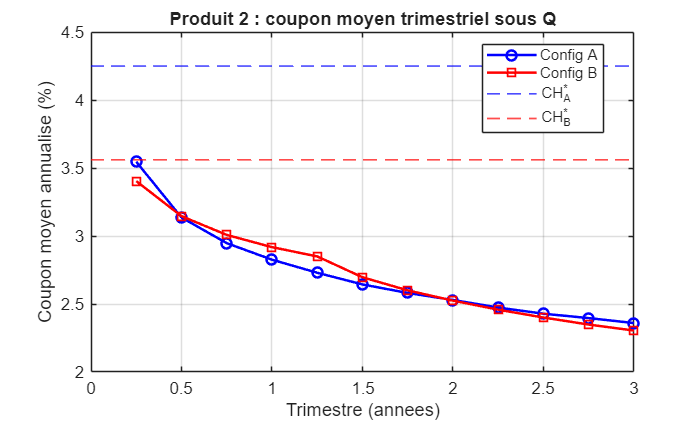


% Visualisation : coupon moyen par trimestre
figure;
plot(t_trim2, 100 * mean(CA_Q, 2), 'b-o', 'LineWidth', 1.5); hold on;
plot(t_trim2, 100 * mean(CB_Q, 2), 'r-s', 'LineWidth', 1.5);
yline(100*CH_A, 'b--', 'LineWidth', 1.0);
yline(100*CH_B, 'r--', 'LineWidth', 1.0);
xlabel('Trimestre (annees)');
ylabel('Coupon moyen annualise (%)');
title('Produit 2 : coupon moyen trimestriel sous Q');
legend('Config A','Config B','CH_A^*','CH_B^*','Location','best');
grid on;

### Analyse de sensibilite

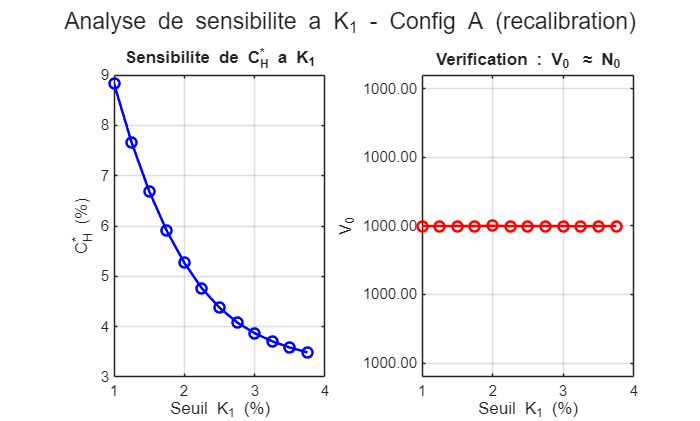


K1_range_A = 0.010 : 0.0025 : 0.040;
CH_K1_A    = zeros(size(K1_range_A));
V0_K1_A    = zeros(size(K1_range_A));

for i = 1:length(K1_range_A)
    K1_i = K1_range_A(i);
    if K1_i >= K2_A
        CH_K1_A(i) = NaN;
        V0_K1_A(i) = NaN;
        continue;
    end
    CH_i = solve_fair_CH(r_Q2,r_avg_Q2, K1_i, K2_A, CM_A, CL_A, Cmem_A, ...
                          dt2, temps_obs2, N0, M2, Delta2);
    CH_K1_A(i) = CH_i;
    if isnan(CH_i)
        V0_K1_A(i) = NaN;
    else
        V0_K1_A(i) = price_product2_Q(r_Q2,r_avg_Q2, K1_i, K2_A, CH_i, CM_A, CL_A, Cmem_A, ...
                          dt2, temps_obs2, N0, M2, Delta2);
    end
end

figure;
subplot(1,2,1);
plot(100*K1_range_A, 100*CH_K1_A, 'b-o', 'LineWidth', 1.5);
xlabel('Seuil K_1 (%)'); ylabel('C_H^* (%)');
title('Sensibilite de C_H^* a K_1');
grid on;

subplot(1,2,2);
plot(100*K1_range_A, V0_K1_A, 'r-o', 'LineWidth', 1.5);
xlabel('Seuil K_1 (%)'); ylabel('V_0');
title('Verification : V_0 \approx N_0');
grid on;
ytickformat('%.2f')   
sgtitle('Analyse de sensibilite a K_1 - Config A (recalibration)');

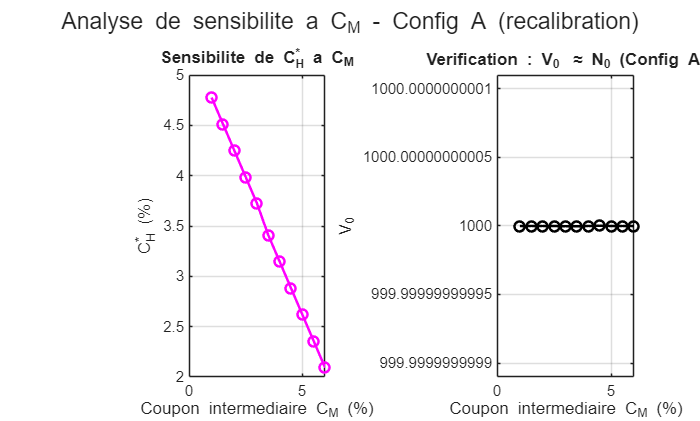

CM_range_A = 0.010 : 0.005 : 0.060;
CH_CM_A    = zeros(size(CM_range_A));
V0_CM_A    = zeros(size(CM_range_A));


for i = 1:length(CM_range_A)
    CM_i = CM_range_A(i);
    CH_i = solve_fair_CH(r_Q2, r_avg_Q2, K1_A, K2_A, CM_i, CL_A, Cmem_A, ...
                          dt2, temps_obs2, N0, M2, Delta2);
    CH_CM_A(i) = CH_i;
    if isnan(CH_i)
        V0_CM_A(i) = NaN;
    else
        V0_CM_A(i) = price_product2_Q(r_Q2, r_avg_Q2, K1_A, K2_A, CH_i, CM_i, CL_A, Cmem_A, ...
                                       dt2, temps_obs2, N0, M2, Delta2);
    end
end

figure;
subplot(1,2,1);
plot(100*CM_range_A, 100*CH_CM_A, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon intermediaire C_M (%)'); ylabel('C_H^* (%)');
title('Sensibilite de C_H^* a C_M');
grid on;

subplot(1,2,2);
plot(100*CM_range_A, V0_CM_A, 'k-o', 'LineWidth', 1.5);
xlabel('Coupon intermediaire C_M (%)'); ylabel('V_0');
title('Verification : V_0 \approx N_0 (Config A)');
grid on;

sgtitle('Analyse de sensibilite a C_M - Config A (recalibration)');

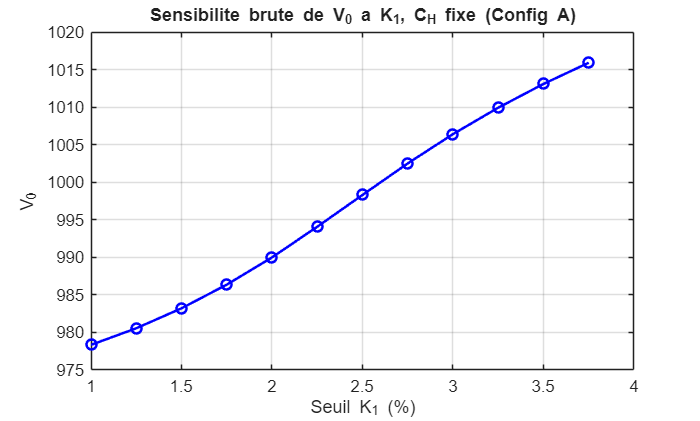


V0_K1_brut_A = zeros(size(K1_range_A));

for i = 1:length(K1_range_A)
    K1_i = K1_range_A(i);
    if K1_i >= K2_A
        V0_K1_brut_A(i) = NaN;
        continue;
    end
    V0_K1_brut_A(i) = price_product2_Q(r_Q2, r_avg_Q2, K1_i, K2_A, CH_A, CM_A, CL_A, Cmem_A, ...
                                         dt2, temps_obs2, N0, M2, Delta2);
end

figure;
plot(100*K1_range_A, V0_K1_brut_A, 'b-o', 'LineWidth', 1.5);
xlabel('Seuil K_1 (%)'); ylabel('V_0');
title('Sensibilite brute de V_0 a K_1, C_H fixe (Config A)');
grid on;

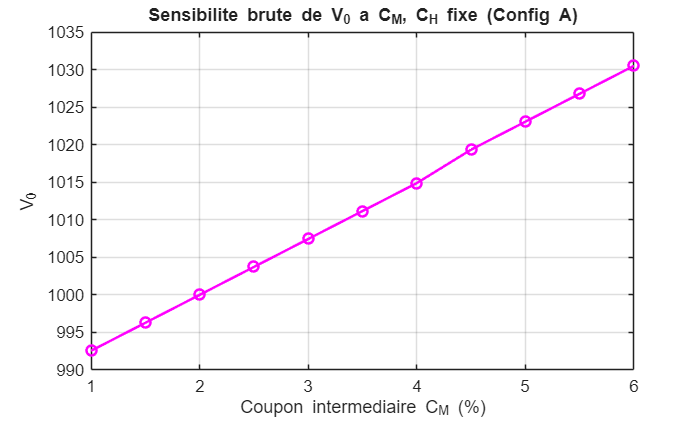

V0_CM_brut_A = zeros(size(CM_range_A));



for i = 1:length(CM_range_A)
    CM_i = CM_range_A(i);
    V0_CM_brut_A(i) = price_product2_Q(r_Q2, r_avg_Q2, K1_A, K2_A, CH_A, CM_i, CL_A, Cmem_A, ...
                                         dt2, temps_obs2, N0, M2, Delta2);
end

figure;
plot(100*CM_range_A, V0_CM_brut_A, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon intermediaire C_M (%)'); ylabel('V_0');
title('Sensibilite brute de V_0 a C_M, C_H fixe (Config A)');
grid on;

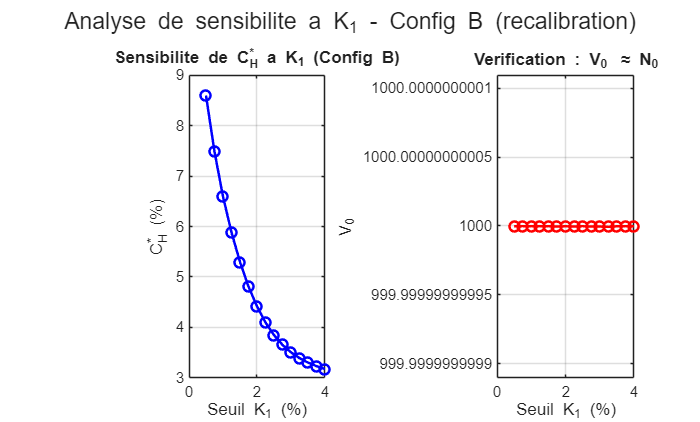

K1_range_B = 0.005 : 0.0025 : 0.040;
CH_K1_B    = zeros(size(K1_range_B));
V0_K1_B    = zeros(size(K1_range_B));

for i = 1:length(K1_range_B)
    K1_i = K1_range_B(i);
    if K1_i >= K2_B
        CH_K1_B(i) = NaN;
        V0_K1_B(i) = NaN;
        continue;
    end
    CH_i = solve_fair_CH(r_Q2, r_avg_Q2, K1_i, K2_B, CM_B, CL_B, Cmem_B, ...
                          dt2, temps_obs2, N0, M2, Delta2);
    CH_K1_B(i) = CH_i;
    if isnan(CH_i)
        V0_K1_B(i) = NaN;
    else
        V0_K1_B(i) = price_product2_Q(r_Q2, r_avg_Q2, K1_i, K2_B, CH_i, CM_B, CL_B, Cmem_B, ...
                                       dt2, temps_obs2, N0, M2, Delta2);
    end
end



figure;
subplot(1,2,1);
plot(100*K1_range_B, 100*CH_K1_B, 'b-o', 'LineWidth', 1.5);
xlabel('Seuil K_1 (%)'); ylabel('C_H^* (%)');
title('Sensibilite de C_H^* a K_1 (Config B)');
grid on;

subplot(1,2,2);
plot(100*K1_range_B, V0_K1_B, 'r-o', 'LineWidth', 1.5);
xlabel('Seuil K_1 (%)'); ylabel('V_0');
title('Verification : V_0 \approx N_0');
grid on;

sgtitle('Analyse de sensibilite a K_1 - Config B (recalibration)');

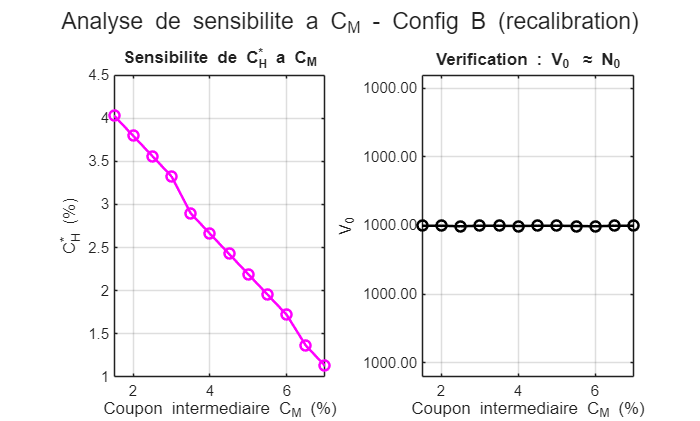

CM_range_B = 0.015 : 0.005 : 0.070;
CH_CM_B    = zeros(size(CM_range_B));
V0_CM_B    = zeros(size(CM_range_B));

for i = 1:length(CM_range_B)
    CM_i = CM_range_B(i);
    CH_i = solve_fair_CH(r_Q2, r_avg_Q2, K1_B, K2_B, CM_i, CL_B, Cmem_B, ...
                          dt2, temps_obs2, N0, M2, Delta2);
    CH_CM_B(i) = CH_i;
    if isnan(CH_i)
        V0_CM_B(i) = NaN;
    else
        V0_CM_B(i) = price_product2_Q(r_Q2, r_avg_Q2, K1_B, K2_B, CH_i, CM_i, CL_B, Cmem_B, ...
                                       dt2, temps_obs2, N0, M2, Delta2);
    end
end



figure;
subplot(1,2,1);
plot(100*CM_range_B, 100*CH_CM_B, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon intermediaire C_M (%)'); ylabel('C_H^* (%)');
title('Sensibilite de C_H^* a C_M');
grid on;

subplot(1,2,2);
plot(100*CM_range_B, V0_CM_B, 'k-o', 'LineWidth', 1.5);
xlabel('Coupon intermediaire C_M (%)'); ylabel('V_0');
title('Verification : V_0 \approx N_0');
grid on;
ytickformat('%.2f')   
sgtitle('Analyse de sensibilite a C_M - Config B (recalibration)');

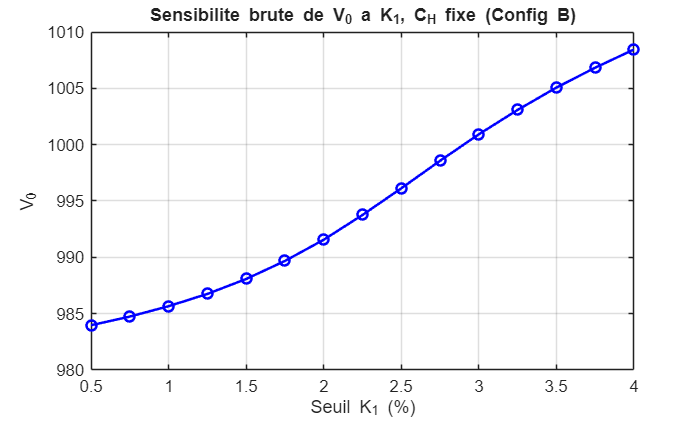

V0_K1_brut_B = zeros(size(K1_range_B));

for i = 1:length(K1_range_B)
    K1_i = K1_range_B(i);
    if K1_i >= K2_B
        V0_K1_brut_B(i) = NaN;
        continue;
    end
    V0_K1_brut_B(i) = price_product2_Q(r_Q2, r_avg_Q2, K1_i, K2_B, CH_B, CM_B, CL_B, Cmem_B, ...
                                         dt2, temps_obs2, N0, M2, Delta2);
end



figure;
plot(100*K1_range_B, V0_K1_brut_B, 'b-o', 'LineWidth', 1.5);
xlabel('Seuil K_1 (%)'); ylabel('V_0');
title('Sensibilite brute de V_0 a K_1, C_H fixe (Config B)');
grid on;

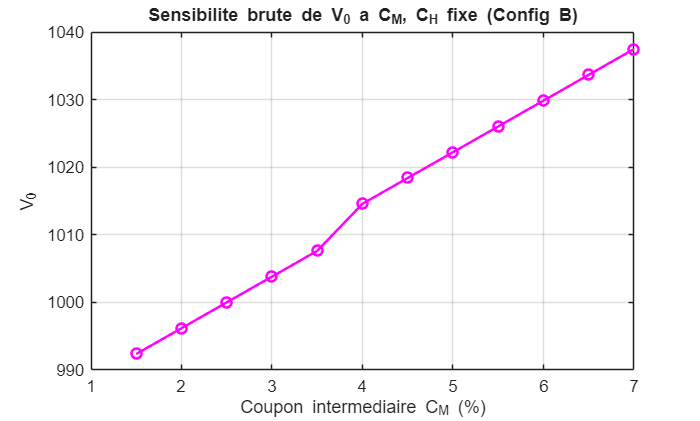

V0_CM_brut_B = zeros(size(CM_range_B));

for i = 1:length(CM_range_B)
    CM_i = CM_range_B(i);
    V0_CM_brut_B(i) = price_product2_Q(r_Q2, r_avg_Q2, K1_B, K2_B, CH_B, CM_i, CL_B, Cmem_B, ...
                                         dt2, temps_obs2, N0, M2, Delta2);
end



figure;
plot(100*CM_range_B, V0_CM_brut_B, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon intermediaire C_M (%)'); ylabel('V_0');
title('Sensibilite brute de V_0 a C_M, C_H fixe (Config B)');
grid on;

### Simulation sous $\mathbb{P}$

% Point de départ : taux observé au 2 avril
r0_P2 = r(end);
rng(12345, 'twister'); 

[r_P2, r_avg_P2] = simulate_vasicek_Q(r0_P2, kappa_hat, theta_P_mle, sigma_hat, ...
                                       dt2, nSteps2, N2, temps_obs2);

% Coupons sous P pour les deux configurations
CA_P = compute_coupons_paliers(r_avg_P2, K1_A, K2_A, CH_A, CM_A, CL_A, Cmem_A);
CB_P = compute_coupons_paliers(r_avg_P2, K1_B, K2_B, CH_B, CM_B, CL_B, Cmem_B);

% Cashflows totaux non actualisés par trajectoire
coupon_total_A_P = N0 * Delta2 * sum(CA_P, 1);   % somme des coupons sur 3 ans
coupon_total_B_P = N0 * Delta2 * sum(CB_P, 1);

CF_total_A_P = N0 + coupon_total_A_P;   % nominal + coupons
CF_total_B_P = N0 + coupon_total_B_P;

% Rendements totaux bruts (en %) sur l'horizon
rendement_A_P = (CF_total_A_P - N0) / N0 * 100;
rendement_B_P = (CF_total_B_P - N0) / N0 * 100;

mean(rendement_A_P)
std(rendement_A_P)

ans = 9.1860

disp(quantile(rendement_A_P, [0.10 0.50 0.90]))

ans = 3.3100

mean(rendement_B_P)

    3.9374    9.9366   12.7485



std(rendement_B_P)

ans = 8.8795

disp(quantile(rendement_B_P, [0.10 0.50 0.90]))

ans = 2.2661

    5.1701    9.8852   10.6802



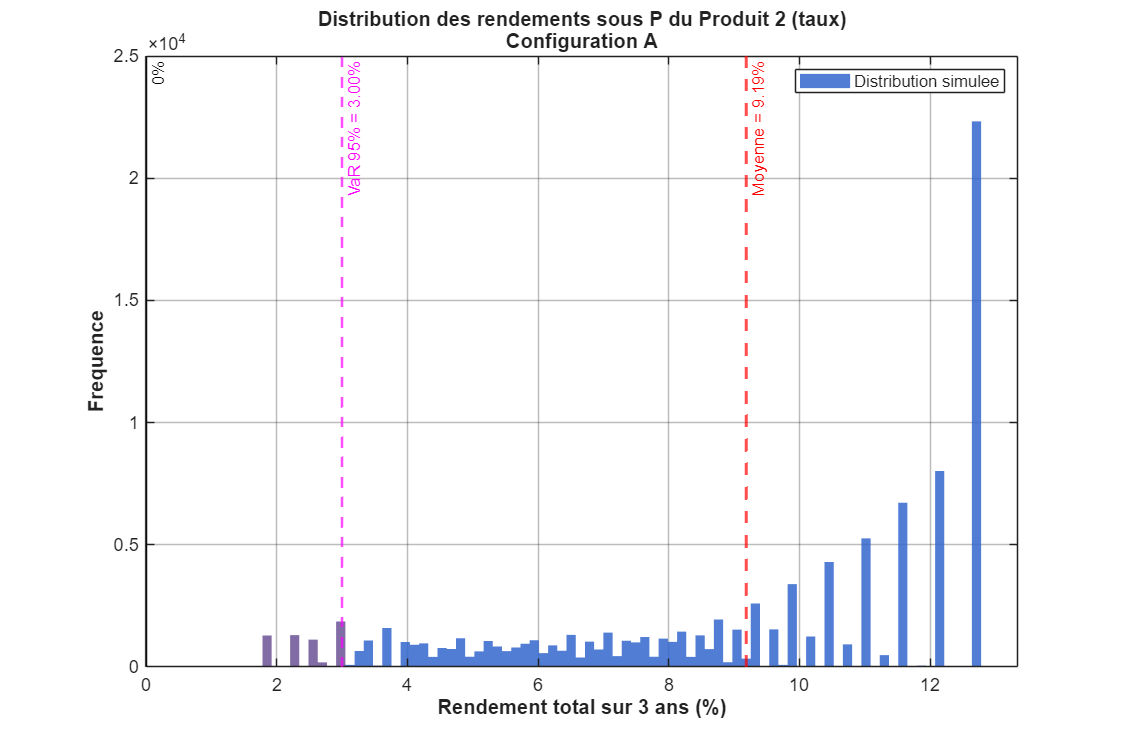

figure('Name', 'Config A Conservatrice - Distribution sous P (Produit 2)', ...
       'Position', [100, 100, 900, 600]);

mu_A      = mean(rendement_A_P);
VaR_95_A  = prctile(rendement_A_P, 5);

% Histogramme
h_A = histogram(rendement_A_P, 80, ...
    'FaceColor', [0.2 0.4 0.8], ...
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.85);
hold on;

% Zone VaR (queue gauche)
binEdges_A   = h_A.BinEdges;
binCounts_A  = h_A.Values;
binCenters_A = (binEdges_A(1:end-1) + binEdges_A(2:end)) / 2;
maskVaR_A    = binCenters_A <= VaR_95_A;

bar(binCenters_A(maskVaR_A), binCounts_A(maskVaR_A), ...
    1.0, ...
    'FaceColor', [0.85 0.3 0.3], ...
    'FaceAlpha', 0.35, ...
    'EdgeColor', 'none');

% Lignes de référence
xline(mu_A, '--r', ...
    ['Moyenne = ' num2str(mu_A, '%.2f') '%'], ...
    'LineWidth', 1.8);

xline(0, '-k', ...
    '0%', ...
    'LineWidth', 1.3);

xline(VaR_95_A, '--m', ...
    ['VaR 95% = ' num2str(VaR_95_A, '%.2f') '%'], ...
    'LineWidth', 1.5);

% Mise en forme
xlabel('Rendement total sur 3 ans (%)', ...
    'FontSize', 12, 'FontWeight', 'bold');
ylabel('Frequence', ...
    'FontSize', 12, 'FontWeight', 'bold');

title({'Distribution des rendements sous P du Produit 2 (taux)', ...
       'Configuration A'}, ...
      'FontSize', 14, ...
      'FontWeight', 'bold', ...
      'Interpreter', 'none');

legend(h_A, 'Distribution simulee', ...
    'Location', 'northeast', ...
    'FontSize', 10);

grid on; box on;
ax = gca; ax.FontSize = 11; ax.GridAlpha = 0.3;

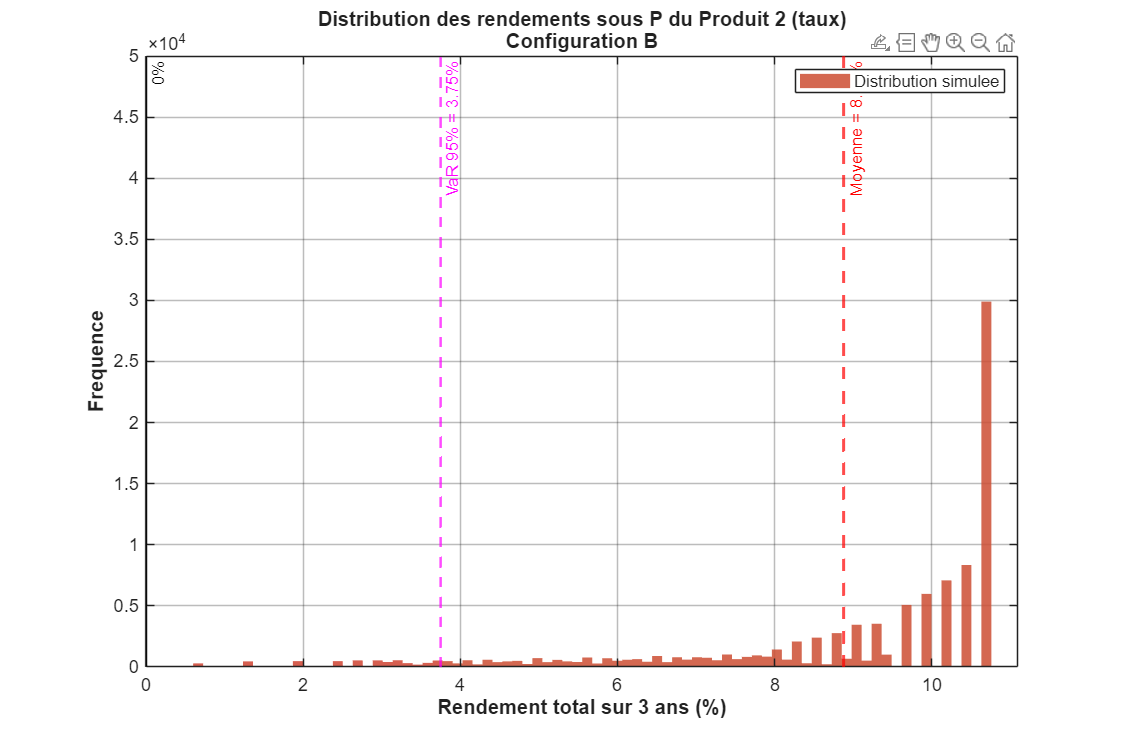


figure('Name', 'Config B Dynamique - Distribution sous P (Produit 2)', ...
       'Position', [150, 150, 900, 600]);

mu_B      = mean(rendement_B_P);
VaR_95_B  = prctile(rendement_B_P, 5);

% Histogramme
h_B = histogram(rendement_B_P, 80, ...
    'FaceColor', [0.8 0.3 0.2], ...
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.85);
hold on;

% Zone VaR (queue gauche)
binEdges_B   = h_B.BinEdges;
binCounts_B  = h_B.Values;
binCenters_B = (binEdges_B(1:end-1) + binEdges_B(2:end)) / 2;
maskVaR_B    = binCenters_B <= VaR_95_B;

bar(binCenters_B(maskVaR_B), binCounts_B(maskVaR_B), ...
    1.0, ...
    'FaceColor', [0.85 0.3 0.3], ...
    'FaceAlpha', 0.35, ...
    'EdgeColor', 'none');

% Lignes de référence
xline(mu_B, '--r', ...
    ['Moyenne = ' num2str(mu_B, '%.2f') '%'], ...
    'LineWidth', 1.8);

xline(0, '-k', ...
    '0%', ...
    'LineWidth', 1.3);

xline(VaR_95_B, '--m', ...
    ['VaR 95% = ' num2str(VaR_95_B, '%.2f') '%'], ...
    'LineWidth', 1.5);

% Mise en forme
xlabel('Rendement total sur 3 ans (%)', ...
    'FontSize', 12, 'FontWeight', 'bold');
ylabel('Frequence', ...
    'FontSize', 12, 'FontWeight', 'bold');

title({'Distribution des rendements sous P du Produit 2 (taux)', ...
       'Configuration B'}, ...
      'FontSize', 14, ...
      'FontWeight', 'bold', ...
      'Interpreter', 'none');

legend(h_B, 'Distribution simulee', ...
    'Location', 'northeast', ...
    'FontSize', 10);

grid on; box on;
ax = gca; ax.FontSize = 11; ax.GridAlpha = 0.3;
ylim([0 5e4])     
alpha = 0.05;


VaR_95_A = prctile(rendement_A_P, alpha * 100)
ES_95_A  = mean(rendement_A_P(rendement_A_P <= VaR_95_A))

VaR_95_A = 3

ES_95_A = 2.4881

VaR_95_B = prctile(rendement_B_P, alpha * 100)
ES_95_B  = mean(rendement_B_P(rendement_B_P <= VaR_95_B))

VaR_95_B = 3.7500

ES_95_B = 2.6470

### Frequences des regimes de coupons sous P

tol = 1e-10;

freq_H_A_P    = mean(abs(CA_P(:) - CH_A) < tol);
freq_M_A_P    = mean(abs(CA_P(:) - CM_A) < tol);
freq_CL_A_P   = mean(abs(CA_P(:) - CL_A) < tol);
freq_mem_A_P  = mean(abs(CA_P(:) - max(CL_A, Cmem_A)) < tol ...
                     & abs(CA_P(:) - CL_A) >= tol);

freq_H_B_P    = mean(abs(CB_P(:) - CH_B) < tol);
freq_M_B_P    = mean(abs(CB_P(:) - CM_B) < tol);
freq_CL_B_P   = mean(abs(CB_P(:) - CL_B) < tol);
freq_mem_B_P  = mean(abs(CB_P(:) - max(CL_B, Cmem_B)) < tol ...
                     & abs(CB_P(:) - CL_B) >= tol);

fprintf('  P(coupon = CH) - Config A       = %.4f\n', freq_H_A_P);
fprintf('  P(coupon = CM)        = %.4f\n', freq_M_A_P);

  P(coupon = CH) - Config A       = 0.5859


fprintf('  P(coupon = CL)        = %.4f\n', freq_CL_A_P);

  P(coupon = CM)        = 0.2347


fprintf('  P(coupon = Cmem)      = %.4f\n', freq_mem_A_P);

  P(coupon = CL)        = 0.1270


freq_H_A_P + freq_M_A_P + freq_CL_A_P + freq_mem_A_P

  P(coupon = Cmem)      = 0.0524


fprintf('  P(coupon = CH) -Config B       = %.4f\n', freq_H_B_P);

ans = 1.0000

fprintf('  P(coupon = CM)        = %.4f\n', freq_M_B_P);

  P(coupon = CH) -Config B       = 0.6547


fprintf('  P(coupon = CL)        = %.4f\n', freq_CL_B_P);

  P(coupon = CM)        = 0.2295


fprintf('  P(coupon = Cmem)      = %.4f\n', freq_mem_B_P);

  P(coupon = CL)        = 0.0790


freq_H_B_P + freq_M_B_P + freq_CL_B_P + freq_mem_B_P

  P(coupon = Cmem)      = 0.0368


ans = 1